# Data Processing - Remove Regeneration

clear % 이전 그래프는 지우지 않는다.
clear all 
close all %  이전 그래프는 지운다.
load B0005.mat
load B0006.mat
load B0007.mat
load B0018.mat
load B0034.mat
load B0036.mat

cap05 = extract_discharge(B0005);
cap06 = extract_discharge(B0006);
cap07 = extract_discharge(B0007);
cap18 = extract_discharge(B0018);
cap34 = extract_discharge(B0034);
cap36 = extract_discharge(B0036);

% A set of four Li-ion batteries (# 5, 6, 7 and 18) 
% were run through 3 different operational profiles (charge, discharge and impedance) at room temperature. 
% Charging was carried out in a constant current (CC) mode at 1.5A until the battery voltage reached 4.2V 
% and then continued in a constant voltage (CV) mode until the charge current dropped to 20mA. 
% Discharge was carried out at a constant current (CC) level of 2A 
% until the battery voltage fell to 2.7V, 2.5V, 2.2V and 2.5V for batteries 5 6 7 and 18 respectively. 
% Impedance measurement was carried out through an electrochemical impedance spectroscopy (EIS) frequency sweep from 0.1Hz to 5kHz. Repeated charge and discharge cycles result in accelerated aging of the batteries while impedance measurements provide insight into the internal battery parameters that change as aging progresses. The experiments were stopped when the batteries reached end-of-life (EOL) criteria, which was a 30% fade in rated capacity (from 2Ahr to 1.4Ahr). This dataset can be used for the prediction of both remaining charge (for a given discharge cycle) and remaining useful life (RUL).


#### room temperature (24 deg C) /  CC Load  (4A,4A,2A)  / 2.0V , 2.2V , 2.7V = 33번 측정이상이 있음.

Data Description:

A set of three Li-ion batteries (# 33, 34 and 36) were run through 3 different operational profiles (charge, discharge and impedance) at room temperature (24 deg C). Charging was carried out in a constant current (CC) mode at 1.5A until the battery voltage reached 4.2V and then continued in a constant voltage (CV) mode until the charge current dropped to 20mA. Discharge was carried out at **4A** until the battery voltage fell to 2.0V and 2.2V for batteries 33 and 34 respectively. For **battery 36 discharge was done at 2A until voltage fell to 2.7V**. Impedance measurement was carried out through an electrochemical impedance spectroscopy (EIS) frequency sweep from 0.1Hz to 5kHz. The experiments were carried out until the capacity had reduced to 1.6Ahr (20% fade).

Files:

B0033.mat	Data for Battery #33

B0034.mat	Data for Battery #34

B0036.mat	Data for Battery #36

pattern_CC_amps = 2;
pattern_restTimeHour = 1; % dynamic 

pattern_dVolt_const05 = 4.2-2.7; % driving range
pattern_CC_amps05 = 2;
pattern_restTimeHour05 = 1; % dynamic 

pattern_dVolt_const06 = 4.2-2.5; % driving range
pattern_CC_amps06 = 2;
pattern_restTimeHour06 = 1; % dynamic 

pattern_dVolt_const07 = 4.2-2.2; % driving range
pattern_CC_amps07 = 2;
pattern_restTimeHour07 = 1; % dynamic 

pattern_dVolt_const18 = 4.2-2.5; % driving range
pattern_CC_amps18 = 2;
pattern_restTimeHour18 = 1; % dynamic 

%  (24 deg C). 
% Charging was carried out in a constant current (CC) mode at 1.5A 
% until the battery voltage reached 4.2V 
% and then continued in a constant voltage (CV) mode 
% until the charge current dropped to 20mA. 
% Discharge was carried out at 4A until the battery voltage fell to 2.0V and 2.2V 
% for batteries 33 and 34 respectively. 
% For battery 36 discharge was done at 2A until voltage fell to 2.7V. 
pattern_dVolt_const33 = 4.2-2.0; % driving range
pattern_CC_amps33 = 4;
pattern_restTimeHour33 = 1; % dynamic 

pattern_dVolt_const34 = 4.2-2.2; % driving range
pattern_CC_amps34 = 4;
pattern_restTimeHour34 = 1; % dynamic 

pattern_dVolt_const36 = 4.2-2.7; % driving range
pattern_CC_amps36 = 2;
pattern_restTimeHour36 = 1; % dynamic 

%result = [cap',cycleTimeHour',restTimeHour',restCycle',cTempMax',cTempMaxDt',cCcEndTimeSec',ohm',re_c',re_d',cycleNoChargeRe',cycleNoDischargeRe',dTempMax',dTempMaxDt',dCcEndTimeSec' ];
%result = [cap',cycleTimeHourHour',restTimeHourHour',restCycle',cTempMax',ohm',re_c',re_d',cycleNoChargeRe',cycleNoDischargeRe',dTempMax',cCcEndTimeSec',dCcEndTimeSec' ];
%result = [cap',cycleTimeHour',restTimeHour',restCycle',cTempMax',cCcEndTimeSec',dTempMax',dCcEndTimeSec',ohm',re_c',re_d',cycleNoChargeRe',cycleNoDischargeRe' ];

i=1;
capacityIdx = i; i=i+1;
cycleTimeHourIdx = i; i=i+1;
restTimeHourIdx = i; i=i+1;
restCycleIdx = i; i=i+1;
cTempMaxIdx = i; i=i+1;
cCcEndTimeSecIdx = i; i=i+1;
dTempMaxIdx = i; i=i+1;
dCcEndTimeSecIdx = i; i=i+1;
ohmIdx = i; i=i+1;
re_cIdx = i; i=i+1;
re_dIdx = i; i=i+1;
cycleNoChageReIdx = i; i=i+1;
cycleNoDischageReIdx = i; i=i+1;
pattern_dVoltIdx = i; i=i+1;

result05_ = extract_feature_all_v2(B0005,0,cap05);
% https://kr.mathworks.com/matlabcentral/answers/269056-how-to-initialize-a-row-vector-with-value-zero-of-size-1xn
pattern_dVolt05_vector = ones(length(result05_),1) * pattern_dVolt_const05; 
result05 = [result05_ pattern_dVolt05_vector];
% https://kr.mathworks.com/matlabcentral/answers/105768-how-can-i-delete-certain-rows-of-a-matrix-based-on-specific-column-values
restCycleTF_raw_index = find (result05(:,restCycleIdx) == 1 )';
result05(restCycleTF_raw_index,:)=[];

i = 1;
capacity05 = result05(:,i)'; i=i+1;
cycleTimeHour05 = result05(:,i)'; i=i+1;
restTimeHour05 = result05(:,i)'; i=i+1;
restCycle05 = result05(:,i)'; i=i+1;
cTempMax05 = result05(:,i)'; i=i+1;
cCcEndTimeSec05 = result05(:,i)'; i=i+1;
ohm05  = result05(:,i)'; i=i+1;
re_c05 =  result05(:,i)'; i=i+1;
re_d05 = result05(:,i)'; i=i+1;
cycleNoChageRe05 = result05(:,i)'; i=i+1;
cycleNoDischageRe05 = result05(:,i)'; i=i+1;
dTempMax05 = result05(:,i)'; i=i+1;
dCcEndTimeSec05 = result05(:,i)'; i=i+1;
pattern_dVolt05 = result05(:,i)'; i=i+1;

%%
result06_ = extract_feature_all_v2(B0006,0,cap06);
pattern_dVolt06_vector = ones(length(result06_),1) * pattern_dVolt_const06; 
result06 = [result06_ pattern_dVolt06_vector];
restCycleTF_raw_index = find (result06(:,restCycleIdx) == 1 )';
result06(restCycleTF_raw_index,:)=[];

i = 1;
capacity06 = result06(:,i)'; i=i+1;
cycleTimeHour06 = result06(:,i)'; i=i+1;
restTimeHour06 = result06(:,i)'; i=i+1;
restCycle06 = result06(:,i)'; i=i+1;
cTempMax06 = result06(:,i)'; i=i+1;
cCcEndTimeSec06 = result06(:,i)'; i=i+1;
ohm06  = result06(:,i)'; i=i+1;
re_c06 =  result06(:,i)'; i=i+1;
re_d06 = result06(:,i)'; i=i+1;
cycleNoChageRe06 = result06(:,i)'; i=i+1;
cycleNoDischageRe06 = result06(:,i)'; i=i+1;
dTempMax06 = result06(:,i)'; i=i+1;
dCcEndTimeSec06 = result06(:,i)'; i=i+1;
pattern_dVolt06 = result06(:,i)'; i=i+1;

%%
result07_ = extract_feature_all_v2(B0007,0,cap07);
pattern_dVolt07_vector = ones(length(result07_),1) * pattern_dVolt_const07; 
result07 = [result07_ pattern_dVolt07_vector];
restCycleTF_raw_index = find (result07(:,restCycleIdx) == 1 )';
result07(restCycleTF_raw_index,:)=[];

i = 1;
capacity07 = result07(:,i)'; i=i+1;
cycleTimeHour07 = result07(:,i)'; i=i+1;
restTimeHour07 = result07(:,i)'; i=i+1;
restCycle07 = result07(:,i)'; i=i+1;
cTempMax07 = result07(:,i)'; i=i+1;
cCcEndTimeSec07 = result07(:,i)'; i=i+1;
ohm07  = result07(:,i)'; i=i+1;
re_c07 =  result07(:,i)'; i=i+1;
re_d07 = result07(:,i)'; i=i+1;
cycleNoChageRe07 = result07(:,i)'; i=i+1;
cycleNoDischageRe07 = result07(:,i)'; i=i+1;
dTempMax07 = result07(:,i)'; i=i+1;
dCcEndTimeSec07 = result07(:,i)'; i=i+1;
pattern_dVolt07 = result07(:,i)'; i=i+1;

%%
result18_ = extract_feature_all_v2(B0018,0,cap18);
pattern_dVolt18_vector = ones(length(result18_),1) * pattern_dVolt_const18; 
result18 = [result18_ pattern_dVolt18_vector];
restCycleTF_raw_index = find (result18(:,restCycleIdx) == 1 )';
result18(restCycleTF_raw_index,:)=[];

i = 1;
capacity18 = result18(:,i)'; i=i+1;
cycleTimeHour18 = result18(:,i)'; i=i+1;
restTimeHour18 = result18(:,i)'; i=i+1;
restCycle18 = result18(:,i)'; i=i+1;
cTempMax18 = result18(:,i)'; i=i+1;
cCcEndTimeSec18 = result18(:,i)'; i=i+1;
ohm18  = result18(:,i)'; i=i+1;
re_c18 =  result18(:,i)'; i=i+1;
re_d18 = result18(:,i)'; i=i+1;
cycleNoChageRe18 = result18(:,i)'; i=i+1;
cycleNoDischageRe18 = result18(:,i)'; i=i+1;
dTempMax18 = result18(:,i)'; i=i+1;
dCcEndTimeSec18 = result18(:,i)'; i=i+1;
pattern_dVolt18 = result18(:,i)'; i=i+1;

%%
result34_ = extract_feature_all_v2(B0034,0,cap34);
pattern_dVolt34_vector = ones(length(result34_),1) * pattern_dVolt_const34; 
result34 = [result34_ pattern_dVolt34_vector];
restCycleTF_raw_index = find (result34(:,restCycleIdx) == 1 )';
result34(restCycleTF_raw_index,:)=[];

i = 1;
capacity34 = result34(:,i)'; i=i+1;
cycleTimeHour34 = result34(:,i)'; i=i+1;
restTimeHour34 = result34(:,i)'; i=i+1;
restCycle34 = result34(:,i)'; i=i+1;
cTempMax34 = result34(:,i)'; i=i+1;
cCcEndTimeSec34 = result34(:,i)'; i=i+1;
ohm34  = result34(:,i)'; i=i+1;
re_c34 =  result34(:,i)'; i=i+1;
re_d34 = result34(:,i)'; i=i+1;
cycleNoChageRe34 = result34(:,i)'; i=i+1;
cycleNoDischageRe34 = result34(:,i)'; i=i+1;
dTempMax34 = result34(:,i)'; i=i+1;
dCcEndTimeSec34 = result34(:,i)'; i=i+1;
pattern_dVolt34 = result34(:,i)'; i=i+1;

result_all = [ result05 ; result06 ; result07 ; result18];

%% org graph - cycle
cycle_number = length(capacity05);

result36_ = extract_feature_all_v2(B0036,0,cap36);
pattern_dVolt36_vector = ones(length(result36_),1) * pattern_dVolt_const36; 
result36 = [result36_ pattern_dVolt36_vector];
restCycleTF_raw_index = find (result36(:,restCycleIdx) == 1 )';
result36(restCycleTF_raw_index,:)=[];

i = 1;
capacity36 = result36(:,i)'; i=i+1;
cycleTimeHour36 = result36(:,i)'; i=i+1;
restTimeHour36 = result36(:,i)'; i=i+1;
restCycle36 = result36(:,i)'; i=i+1;
cTempMax36 = result36(:,i)'; i=i+1;
cCcEndTimeSec36 = result36(:,i)'; i=i+1;
ohm36  = result36(:,i)'; i=i+1;
re_c36 =  result36(:,i)'; i=i+1;
re_d36 = result36(:,i)'; i=i+1;
cycleNoChageRe36 = result36(:,i)'; i=i+1;
cycleNoDischageRe36 = result36(:,i)'; i=i+1;
dTempMax36 = result36(:,i)'; i=i+1;
dCcEndTimeSec36 = result36(:,i)'; i=i+1;
pattern_dVolt36 = result36(:,i)'; i=i+1;

% new data set #01 / #02
result05(58,1)

ans = 1.5015

result06(53,1)

ans = 1.4876

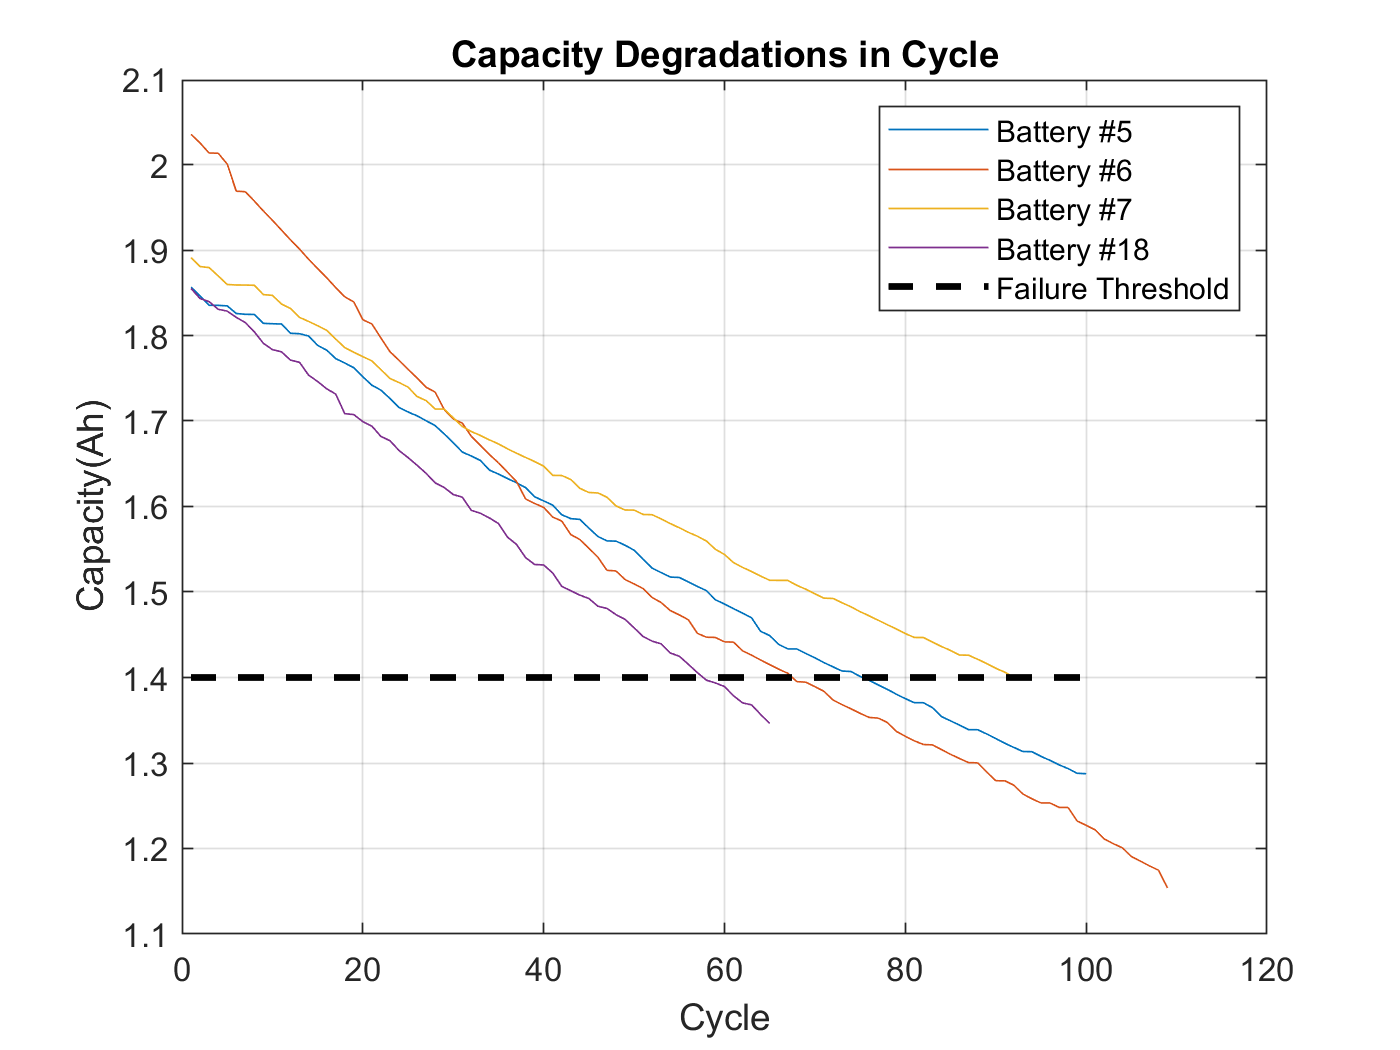


% ignore rest time , maxTempDt 
result05_06 = [ result05(1:58,:) ; result06(:,53:end) ];
result06_05 = [ result06(1:53,:) ; result05(:,58:end) ];
result_05_06_all = [ result05 ; result06 ];



result_all = [ result05 ; result06 ; result07 ; result18];
%% org graph - cycle
cycle_number = length(capacity05);

figure
plot(capacity05), hold on, plot(capacity06), plot(capacity07), plot(capacity18)
plot(1:cycle_number, 1.4*ones(1, cycle_number),'k--','LineWidth', 2)
hold off, grid on
xlabel Cycle, ylabel Capacity(Ah)
legend('Battery #5', 'Battery #6', 'Battery #7', 'Battery #18','Failure Threshold')
title('Capacity Degradations in Cycle')

#6 index 53 (58) 

#5 index 58 (64) 

에서 1.70으로 겹친다.

여기서 두개의 데이타 셋을 만든다.

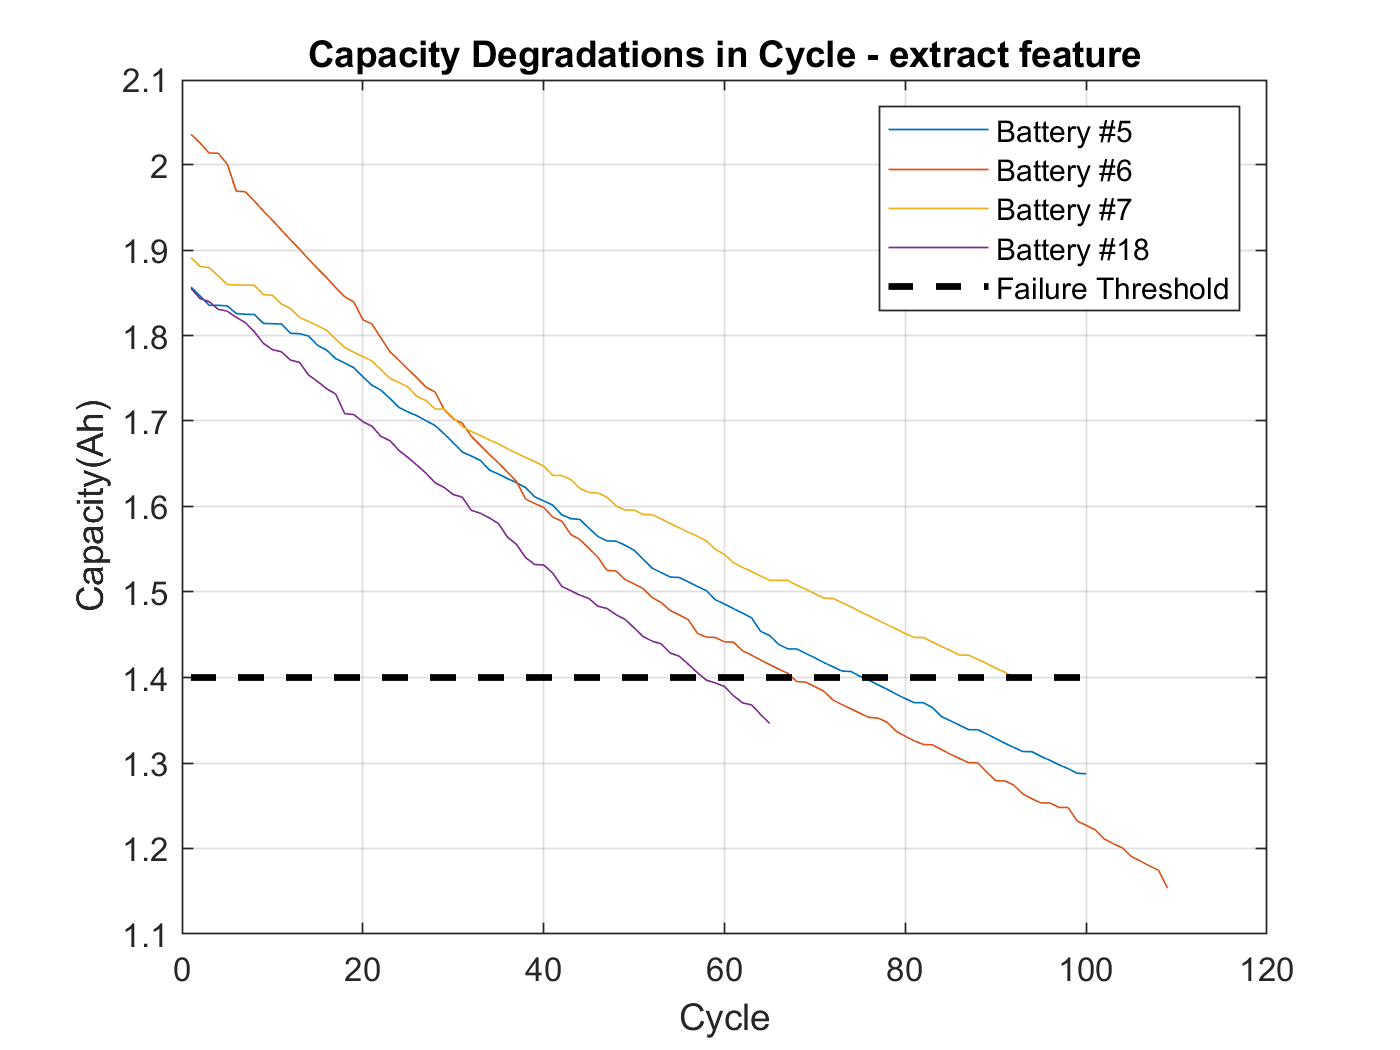



%% new graph using my function - cycle
figure
plot(capacity05), hold on, plot(capacity06), plot(capacity07), plot(capacity18)
plot(1:cycle_number, 1.4*ones(1, cycle_number),'k--','LineWidth', 2)
hold off, grid on
xlabel Cycle, ylabel Capacity(Ah)
legend('Battery #5', 'Battery #6', 'Battery #7', 'Battery #18','Failure Threshold')
title('Capacity Degradations in Cycle - extract feature')

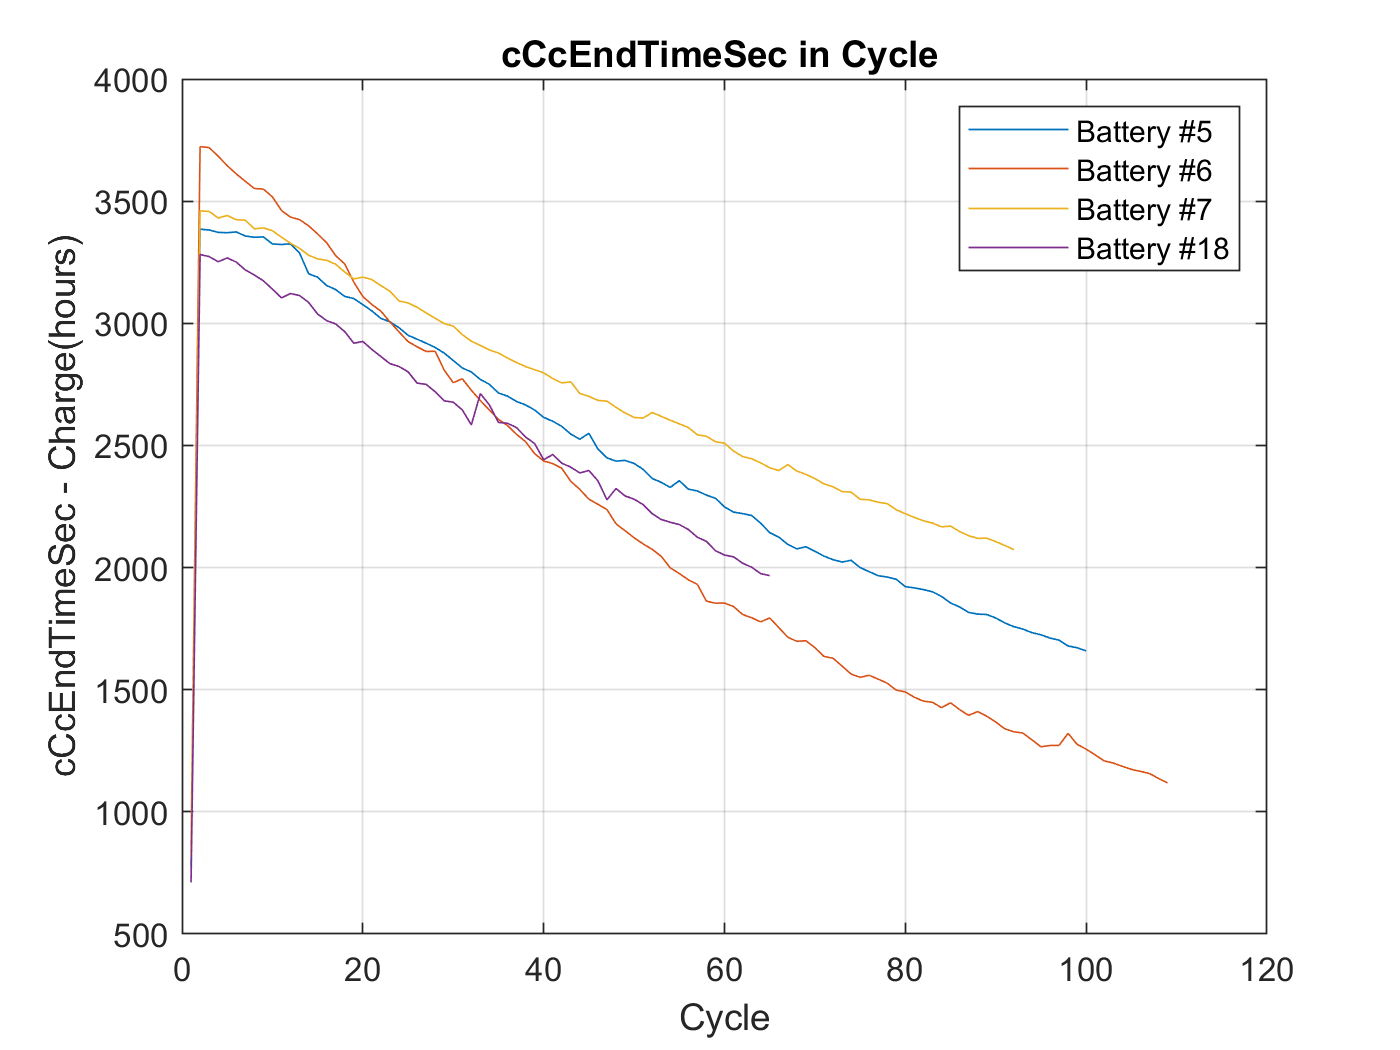

%% check outlier

figure
plot(cCcEndTimeSec05), hold on,plot(cCcEndTimeSec06),plot(cCcEndTimeSec07),plot(cCcEndTimeSec18),hold off, grid on
xlabel Cycle, ylabel 'cCcEndTimeSec - Charge(hours)'
%legend('Battery #5', 'Battery #6', 'Battery #7')
legend('Battery #5', 'Battery #6', 'Battery #7','Battery #18')
title('cCcEndTimeSec in Cycle ')

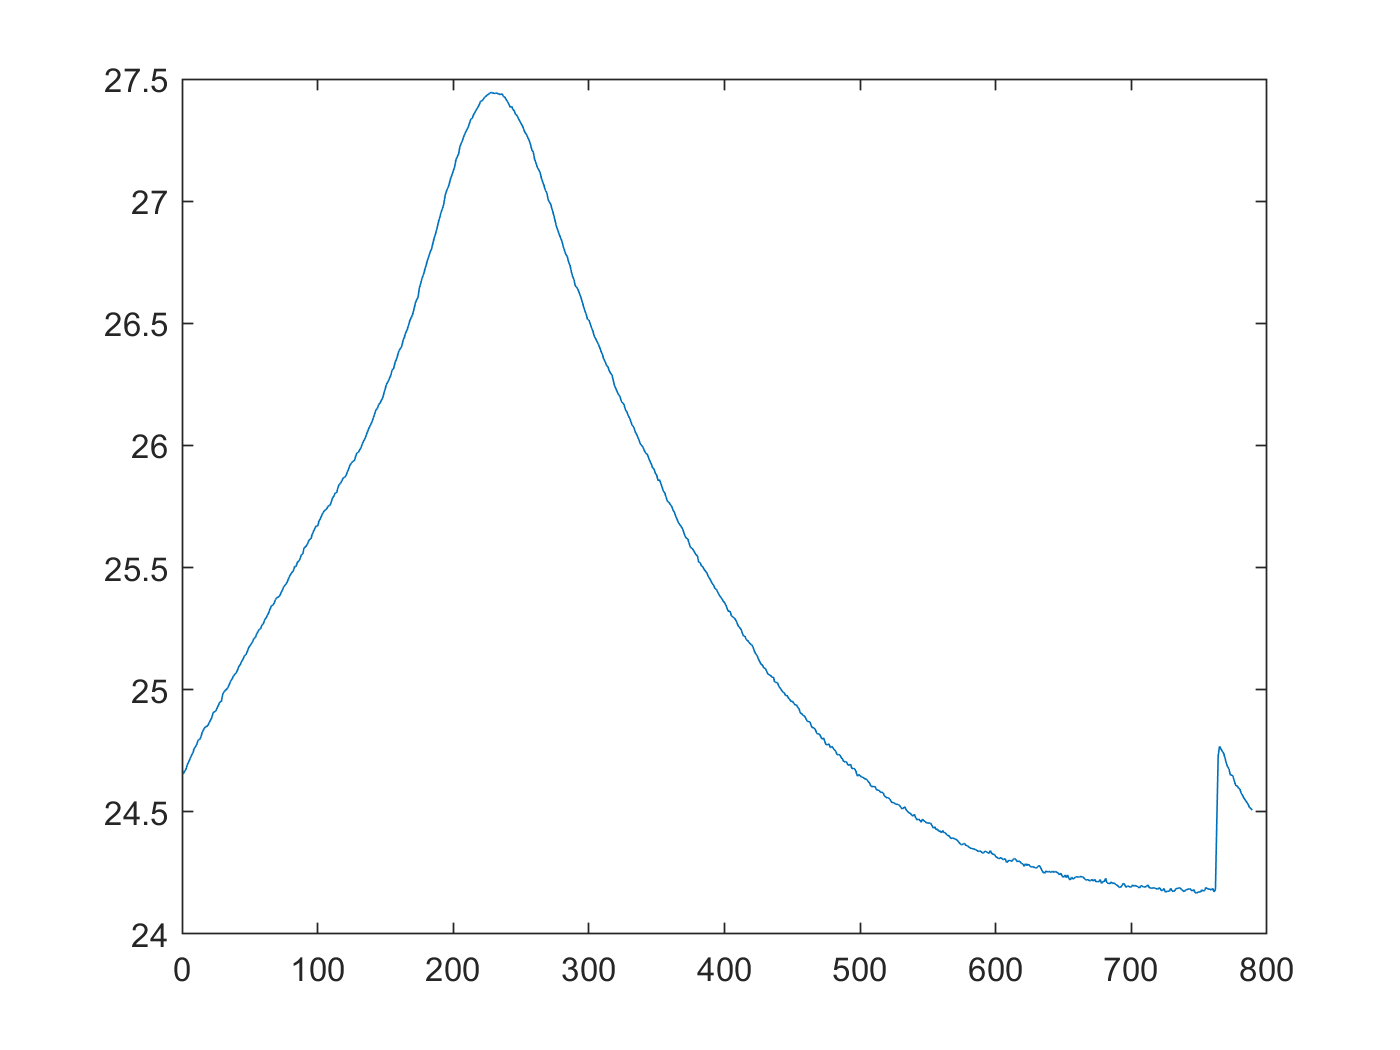


%result = [cap,cTemp,cTime,cV,cI,cVcharge,cIcharge,dTemp,dTime,dV,dI,dIload,icCsense,icCbattery,icCratio,icBatImp,icRecImp,idCsense,idCbattery,idCratio,idBatImp,idRecImp ];
%[cap,cTemp,cTime,cV,cI,cVcharge,cIcharge,dTemp,dTime,dV,dI,dIload,icCsense,icCbattery,icCratio,icBatImp,icRecImp,idCsense,idCbattery,idCratio,idBatImp,idRecImp ] ...
    %= extract_raw_data(B0005,1);
[cap,cTemp,cTime,cV,cI,cVcharge,cIcharge,dTemp,dTime,dV,dI,dIload ] ...
    = extract_raw_data(B0005,1);

figure
plot(cTemp)

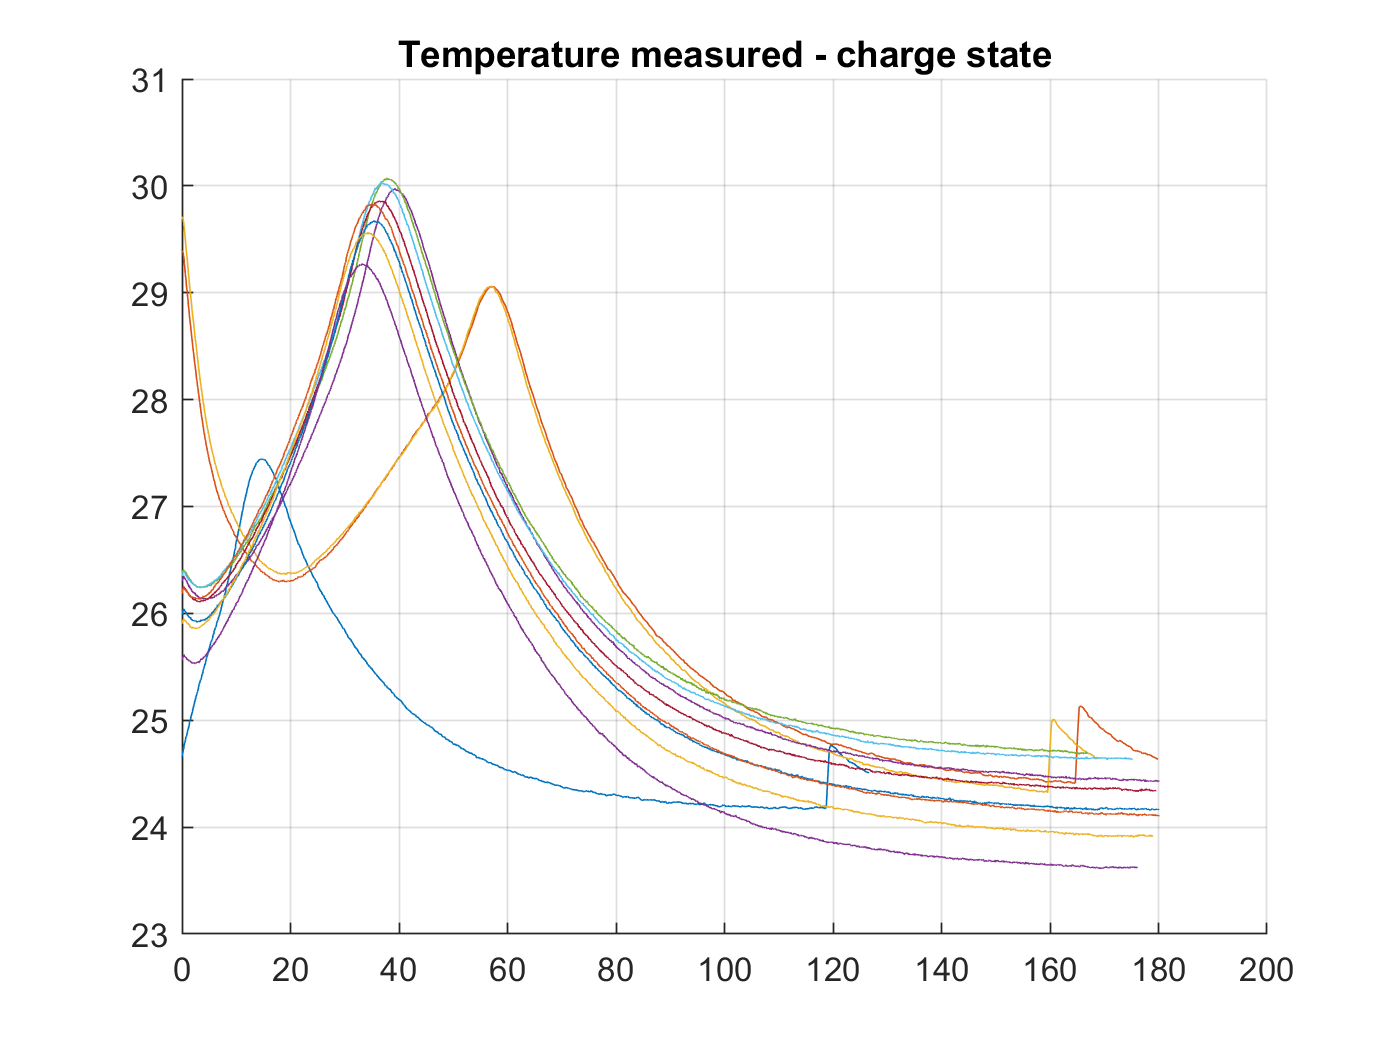



figure
hold on
items = size(B0005.cycle,2);
for i=1:items
    if isequal(B0005.cycle(i).type, 'charge')
        if mod(i , 10 ) == 1
            k = mod (round(i / 10), 10 ) + 1;
            plot(B0005.cycle(i).data.Time/60,B0005.cycle(i).data.Temperature_measured)
        end
    end
end
hold off 
title("Temperature measured - charge state")
grid on

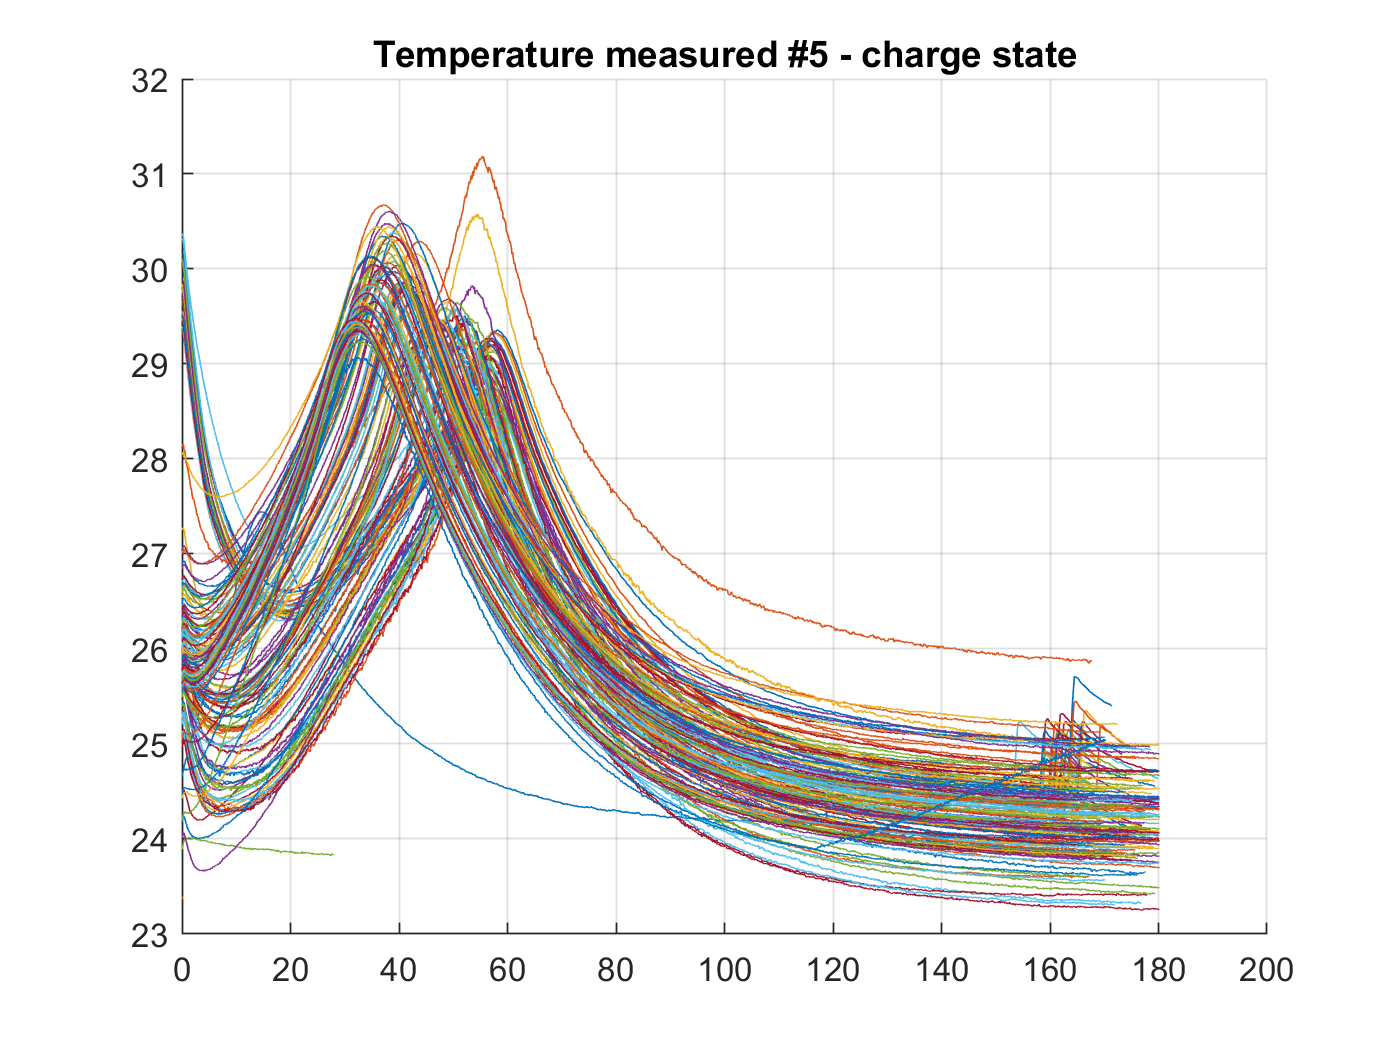


% https://kr.mathworks.com/matlabcentral/fileexchange/21050-varycolor
% https://blogs.mathworks.com/pick/2008/08/15/colors-for-your-multi-line-plots/?from=kr

items = size(B0005.cycle,2);

figure
ColorSet = varycolor(items);
hold all;
for i=1:items
    if isequal(B0005.cycle(i).type, 'charge')
        %if mod(i , 10 ) == 1
            k = mod (round(i / 10), 10 ) + 1;
            plot(B0005.cycle(i).data.Time/60,B0005.cycle(i).data.Temperature_measured)
        %end
    end
end
hold off 
title("Temperature measured #5 - charge state")
grid on


temp_B18_19 = B0018.cycle(19).data.Temperature_measured

temp_B18_19 =    36.1867   36.1535   36.1301   36.1127   36.0760   36.0429   36.0002   35.9569   35.9040   35.8626   35.8118   35.7616   35.7143   35.6644   35.6151   35.5730   35.5239   35.4833   35.4340   35.3837   35.3436   35.2929   35.2360   35.1931   35.1531   35.1061   35.0537   35.0122   34.9617   34.9027   34.8544   34.8043   34.7614   34.7192   34.6788   34.6349   34.5852   34.5412   34.4930   34.4541   34.3987   34.3659   34.3115   34.2694   34.2279   34.1767   34.1279   34.0850   34.0493   34.0011




items = size(B0018.cycle,2);
cTempMaxIndex = [];


figure
ColorSet = varycolor(items);
hold all;
k=1

k = 1

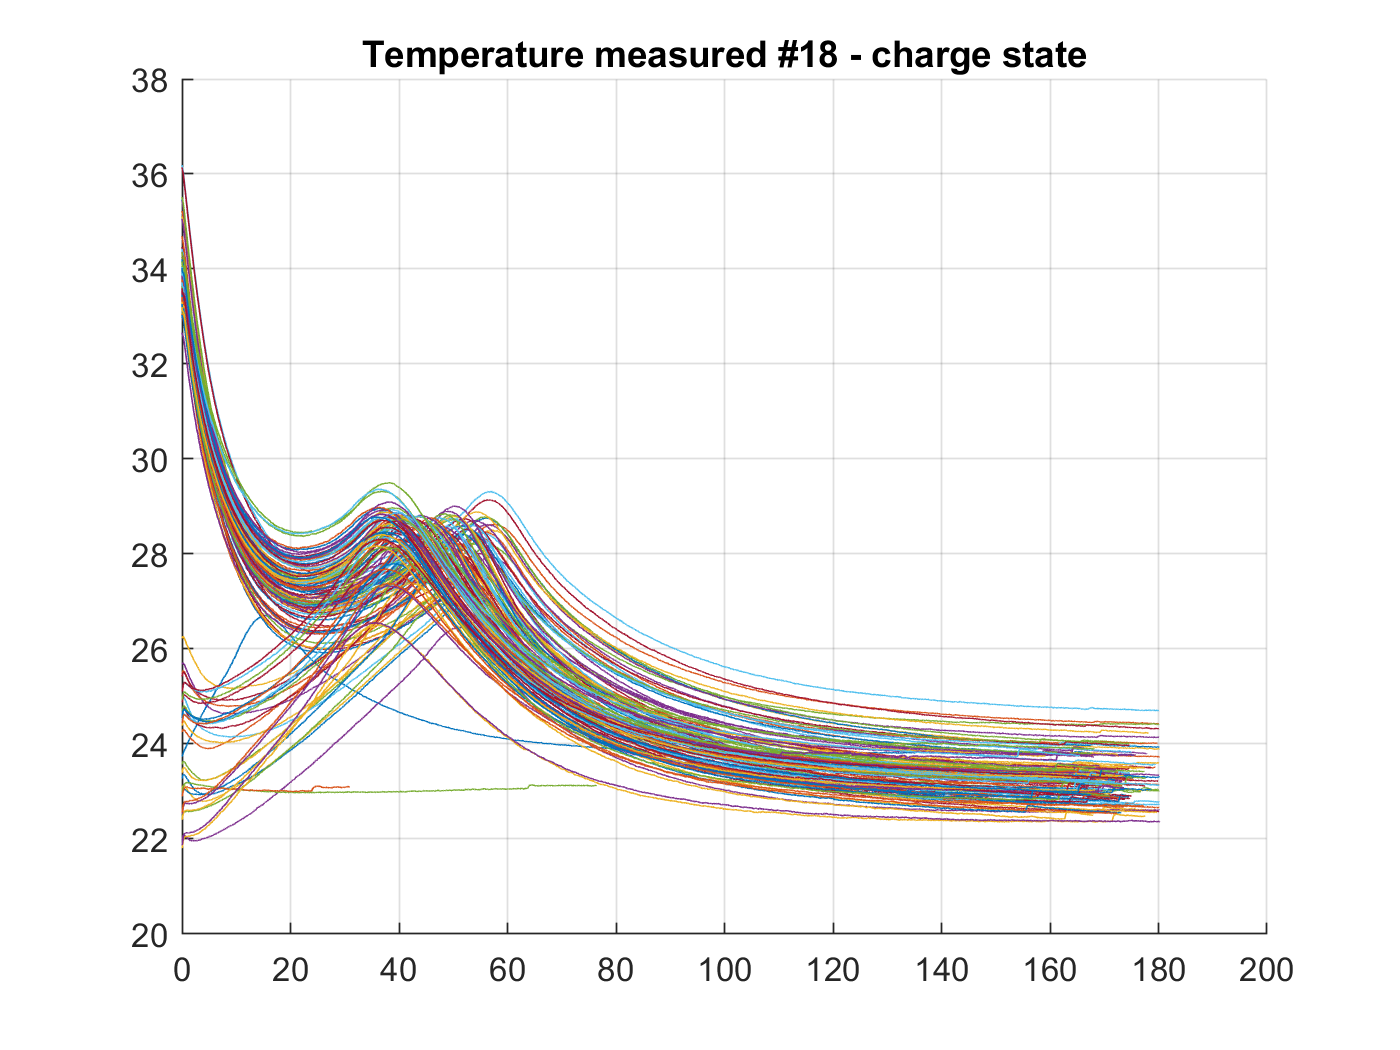

for i=1:items
    if isequal(B0018.cycle(i).type, 'charge')
        %if mod(i , 10 ) == 1
            %k = mod (round(i / 10), 10 ) + 1;
            plot(B0018.cycle(i).data.Time/60, B0018.cycle(i).data.Temperature_measured)
            temp = B0018.cycle(i).data.Temperature_measured;
            cTempMaxGuess = islocalmax(temp,'MinProminence',2);
            if sum(cTempMaxGuess(:) == 1 ) == 0 
               cTempMaxGuess = islocalmax(temp,'MinProminence',1);
            end
            
            if sum(cTempMaxGuess(:) == 1 ) == 0 
                smoothed = smoothdata(B0018.cycle(i).data.Temperature_measured);
                cTempMaxGuess = islocalmax(smoothed,'MinProminence',2);
                if sum(cTempMaxGuess(:) == 1 ) == 0 
                   cTempMaxGuess = islocalmax(smoothed,'MinProminence',1);
                end
            end

            if sum(cTempMaxGuess(:) == 1 ) == 0 
                cTempMaxIndex(k) = max(temp);            
            else 
                cTempMaxIndex(k) = find(cTempMaxGuess, 1, 'first');  
            end
            k = k+1;
        %end
    end
end
hold off 
title("Temperature measured #18 - charge state")
grid on


%{
%% index
i=1;
capacityIdx = i; i=i+1;
cycleTimeHourIdx = i; i=i+1;
restTimeHourIdx = i; i=i+1;
restCycleIdx = i; i=i+1;
cTempMaxIdx = i; i=i+1;
cCcEndTimeSecIdx = i; i=i+1;
dTempMaxIdx = i; i=i+1;
dCcEndTimeSecIdx = i; i=i+1;
ohmIdx = i; i=i+1;
re_cIdx = i; i=i+1;
re_dIdx = i; i=i+1;
cycleNoChageReIdx = i; i=i+1;
cycleNoDischageReIdx = i; i=i+1;
pattern_dVoltIdx = i; i=i+1;
%}

%% create vector / table
    
regression_vector05 = [ ...
    result05(:, cCcEndTimeSecIdx ) ...
    result05(:, ohmIdx ) ...
    result05(:, pattern_dVoltIdx ) ...
    result05(:, capacityIdx ) ] ;

regression_vector06 = [ ...
    result06(:, cCcEndTimeSecIdx ) ...
    result06(:, ohmIdx ) ...
    result06(:, pattern_dVoltIdx ) ...
    result06(:, capacityIdx ) ] ;

regression_vector07 = [ ...
    result07(:, cCcEndTimeSecIdx ) ...
    result07(:, ohmIdx ) ...
    result07(:, pattern_dVoltIdx ) ...
    result07(:, capacityIdx ) ] ;

regression_vector18 = [ ...
    result18(:, cCcEndTimeSecIdx ) ...
    result18(:, ohmIdx ) ...
    result18(:, pattern_dVoltIdx ) ...
    result18(:, capacityIdx ) ] ;

regression_vector_all = [ ...
    result_all(:, cCcEndTimeSecIdx ) ...
    result_all(:, ohmIdx ) ...
    result_all(:, pattern_dVoltIdx ) ...
    result_all(:, capacityIdx ) ] ;

regression_vector_05_06_all = [ ...
    result_05_06_all(:, cCcEndTimeSecIdx ) ...
    result_05_06_all(:, ohmIdx ) ...
    result_05_06_all(:, pattern_dVoltIdx ) ...
    result_05_06_all(:, capacityIdx ) ] ;

regression_vector05_06 = [ ...
    result05_06(:, cCcEndTimeSecIdx ) ...
    result05_06(:, ohmIdx ) ...
    result05_06(:, pattern_dVoltIdx ) ...
    result05_06(:, capacityIdx ) ] ;

regression_vector06_05 = [ ...
    result06_05(:, cCcEndTimeSecIdx ) ...
    result06_05(:, ohmIdx ) ...
    result06_05(:, pattern_dVoltIdx ) ...
    result06_05(:, capacityIdx ) ] ;

% works
regression_table05 = array2table(regression_vector05,...
    'VariableNames',{'cCcEndTimeSec','ohm','pattern_dVolt','capacity'});

regression_table06 = array2table(regression_vector06,...
    'VariableNames',{'cCcEndTimeSec','ohm','pattern_dVolt','capacity'});

regression_table05_06 = array2table(regression_vector05_06,...
    'VariableNames',{'cCcEndTimeSec','ohm','pattern_dVolt','capacity'});

regression_table06_05 = array2table(regression_vector06_05,...
    'VariableNames',{'cCcEndTimeSec','ohm','pattern_dVolt','capacity'});

regression_table_05_06_all = array2table(regression_vector_05_06_all,...
    'VariableNames',{'cCcEndTimeSec','ohm','pattern_dVolt','capacity'});

regression_table07 = array2table(regression_vector07,...
    'VariableNames',{'cCcEndTimeSec','ohm','pattern_dVolt','capacity'});

regression_table18 = array2table(regression_vector18,...
    'VariableNames',{'cCcEndTimeSec','ohm','pattern_dVolt','capacity'});

regression_table_all = array2table(regression_vector_all,...
    'VariableNames',{'cCcEndTimeSec','ohm','pattern_dVolt','capacity'});
    
% https://kr.mathworks.com/help/matlab/ref/cell2table.html    
% works
%{
regression_table_5 = array2table(regression_vector05,...
    'VariableNames',{'cCcEndTimeSec','ohm','capacity'});

regression_table_6 = array2table(regression_vector06,...
    'VariableNames',{'cCcEndTimeSec','ohm','capacity'});
%}


## corellaton

%{ 
% error after adding pattern_dVolt
figure
[R5,PValue5] = corrplot(regression_vector05,'type','Pearson','testR','on','varNames',{'cCcEndTimeSec','ohm','pattern_dVolt','capacity'})
figure
[R6,PValue6] = corrplot(regression_vector06,'type','Pearson','testR','on','varNames',{'cCcEndTimeSec','ohm','pattern_dVolt','capacity'})
%}

%% linear regression

% https://kr.mathworks.com/help/stats/fitlm.html
modelspec = ' capacity ~  cCcEndTimeSec + ohm + pattern_dVolt '

modelspec = ' capacity ~  cCcEndTimeSec + ohm + pattern_dVolt '

modelspecSingleX = ' capacity ~  cCcEndTimeSec + pattern_dVolt '

modelspecSingleX = ' capacity ~  cCcEndTimeSec + pattern_dVolt '

mdl = fitlm(regression_table_all,modelspec )

mdl = Linear regression model:
    capacity ~ 1 + cCcEndTimeSec + ohm + pattern_dVolt

Estimated Coefficients:
                      Estimate         SE         tStat       pValue  
                     __________    __________    _______    __________

    (Intercept)          1.4102      0.065638     21.485     1.346e-66
    cCcEndTimeSec    0.00018456    1.0721e-05     17.215    5.9963e-49
    ohm                 -108.95        11.317    -9.6278    1.1018e-19
    pattern_dVolt      0.021175      0.024255    0.87302       0.38323


Number of observations: 366, Error degrees of freedom: 362
Root Mean Squared Error: 0.0829
R-squared: 0.819,  Adjusted R-Squared: 0.817
F-statistic vs. constant model: 546, p-value = 6.53e-134

mdlSingleX = fitlm(regression_table_all,modelspecSingleX )

mdlSingleX = Linear regression model:
    capacity ~ 1 + cCcEndTimeSec + pattern_dVolt

Estimated Coefficients:
                      Estimate         SE          tStat        pValue   
                     __________    __________    _________    ___________

    (Intercept)         0.92747      0.047406       19.564     1.0282e-58
    cCcEndTimeSec    0.00026423    7.6274e-06       34.643    3.9106e-117
    pattern_dVolt    -0.0018406      0.027014    -0.068135        0.94572


Number of observations: 366, Error degrees of freedom: 363
Root Mean Squared Error: 0.0928
R-squared: 0.773,  Adjusted R-Squared: 0.771
F-statistic vs. constant model: 616, p-value = 1.88e-117


mdl5 = fitlm(regression_table05,modelspec )

mdl5 = Linear regression model:
    capacity ~ 1 + cCcEndTimeSec + ohm + pattern_dVolt

Estimated Coefficients:
                      Estimate         SE        tStat       pValue  
                     __________    __________    ______    __________

    (Intercept)               0             0       NaN           NaN
    cCcEndTimeSec    0.00018149    1.6757e-05    10.831    2.4724e-18
    ohm                 -138.13        17.821    -7.751    9.5253e-12
    pattern_dVolt        1.0123      0.058298    17.364    2.2339e-31


Number of observations: 100, Error degrees of freedom: 97
Root Mean Squared Error: 0.0646
R-squared: 0.867,  Adjusted R-Squared: 0.865
F-statistic vs. constant model: 317, p-value = 2.85e-43

mdlSingleX5 = fitlm(regression_table05,modelspecSingleX )

mdlSingleX5 = Linear regression model:
    capacity ~ 1 + cCcEndTimeSec + pattern_dVolt

Estimated Coefficients:
                      Estimate         SE        tStat       pValue  
                     __________    __________    ______    __________

    (Intercept)               0             0       NaN           NaN
    cCcEndTimeSec    0.00027586    1.4577e-05    18.925    2.4892e-34
    pattern_dVolt       0.58586      0.024419    23.992    1.4206e-42


Number of observations: 100, Error degrees of freedom: 98
Root Mean Squared Error: 0.0818
R-squared: 0.785,  Adjusted R-Squared: 0.783
F-statistic vs. constant model: 358, p-value = 1.7e-34

mdl6 = fitlm(regression_table06,modelspec )

mdl6 = Linear regression model:
    capacity ~ 1 + cCcEndTimeSec + ohm + pattern_dVolt

Estimated Coefficients:
                      Estimate        SE        tStat       pValue  
                     __________    ________    _______    __________

    (Intercept)               0           0        NaN           NaN
    cCcEndTimeSec    0.00014023    1.63e-05     8.6032    8.1714e-14
    ohm                 -167.66      16.212    -10.342    1.0476e-17
    pattern_dVolt        1.0489    0.051014     20.562      1.32e-38


Number of observations: 109, Error degrees of freedom: 106
Root Mean Squared Error: 0.0624
R-squared: 0.939,  Adjusted R-Squared: 0.938
F-statistic vs. constant model: 812, p-value = 5.3e-65

mdlSingleX6 = fitlm(regression_table06,modelspecSingleX )

mdlSingleX6 = Linear regression model:
    capacity ~ 1 + cCcEndTimeSec + pattern_dVolt

Estimated Coefficients:
                      Estimate        SE        tStat       pValue  
                     __________    _________    ______    __________

    (Intercept)               0            0       NaN           NaN
    cCcEndTimeSec    0.00029016    1.051e-05    27.609    3.2234e-50
    pattern_dVolt       0.53179     0.014231    37.369    7.4947e-63


Number of observations: 109, Error degrees of freedom: 107
Root Mean Squared Error: 0.088
R-squared: 0.877,  Adjusted R-Squared: 0.876
F-statistic vs. constant model: 762, p-value = 1.74e-50

mdl5_6 = fitlm(regression_table05_06,modelspec )

mdl5_6 = Linear regression model:
    capacity ~ 1 + cCcEndTimeSec + ohm + pattern_dVolt

Estimated Coefficients:
                      Estimate         SE         tStat       pValue  
                     __________    __________    _______    __________

    (Intercept)               0             0        NaN           NaN
    cCcEndTimeSec    8.2091e-05    2.0428e-05     4.0186    0.00018273
    ohm                 -127.65        16.657    -7.6638    3.4481e-10
    pattern_dVolt        1.1952      0.059458     20.101    9.7733e-27


Number of observations: 58, Error degrees of freedom: 55
Root Mean Squared Error: 0.0601
R-squared: 0.719,  Adjusted R-Squared: 0.709
F-statistic vs. constant model: 70.3, p-value = 6.98e-16

mdl6_5 = fitlm(regression_table06_05,modelspec )

mdl6_5 = Linear regression model:
    capacity ~ 1 + cCcEndTimeSec + ohm + pattern_dVolt

Estimated Coefficients:
                      Estimate         SE         tStat       pValue  
                     __________    __________    _______    __________

    (Intercept)               0             0        NaN           NaN
    cCcEndTimeSec    4.5674e-05    2.1827e-05     2.0926      0.041587
    ohm                 -179.62        16.851    -10.659    2.3187e-14
    pattern_dVolt        1.2353      0.058967     20.949    4.2034e-26


Number of observations: 53, Error degrees of freedom: 50
Root Mean Squared Error: 0.0641
R-squared: 0.861,  Adjusted R-Squared: 0.856
F-statistic vs. constant model: 155, p-value = 3.59e-22

mdl_05_06 = fitlm(regression_table_05_06_all,modelspec )

mdl_05_06 = Linear regression model:
    capacity ~ 1 + cCcEndTimeSec + ohm + pattern_dVolt

Estimated Coefficients:
                      Estimate         SE        tStat       pValue  
                     __________    __________    ______    __________

    (Intercept)          1.0345      0.090875    11.384    1.3796e-23
    cCcEndTimeSec    0.00016065    1.1666e-05    13.771     5.595e-31
    ohm                  -150.9        11.835    -12.75    8.4727e-28
    pattern_dVolt       0.38181      0.045537    8.3847    8.1298e-15


Number of observations: 209, Error degrees of freedom: 205
Root Mean Squared Error: 0.0637
R-squared: 0.915,  Adjusted R-Squared: 0.914
F-statistic vs. constant model: 740, p-value = 1.22e-109


mdl7 = fitlm(regression_table07,modelspec )

mdl7 = Linear regression model:
    capacity ~ 1 + cCcEndTimeSec + ohm + pattern_dVolt

Estimated Coefficients:
                      Estimate         SE         tStat       pValue  
                     __________    __________    _______    __________

    (Intercept)               0             0        NaN           NaN
    cCcEndTimeSec    0.00016415    1.6991e-05     9.6608    1.7891e-15
    ohm                  -171.2        18.621    -9.1941    1.6353e-14
    pattern_dVolt       0.83708      0.044073     18.993    6.9924e-33


Number of observations: 92, Error degrees of freedom: 89
Root Mean Squared Error: 0.0626
R-squared: 0.819,  Adjusted R-Squared: 0.815
F-statistic vs. constant model: 201, p-value = 9.73e-34

mdlSingleX7 = fitlm(regression_table07,modelspecSingleX )

mdlSingleX7 = Linear regression model:
    capacity ~ 1 + cCcEndTimeSec + pattern_dVolt

Estimated Coefficients:
                      Estimate        SE        tStat       pValue  
                     __________    _________    ______    __________

    (Intercept)               0            0       NaN           NaN
    cCcEndTimeSec    0.00025131    1.958e-05    12.835    5.8894e-22
    pattern_dVolt       0.47307     0.026889    17.593    1.0166e-30


Number of observations: 92, Error degrees of freedom: 90
Root Mean Squared Error: 0.0869
R-squared: 0.647,  Adjusted R-Squared: 0.643
F-statistic vs. constant model: 165, p-value = 4.81e-22


mdl18 = fitlm(regression_table18,modelspec )

mdl18 = Linear regression model:
    capacity ~ 1 + cCcEndTimeSec + ohm + pattern_dVolt

Estimated Coefficients:
                      Estimate         SE         tStat       pValue  
                     __________    __________    _______    __________

    (Intercept)               0             0        NaN           NaN
    cCcEndTimeSec    0.00022135    2.0525e-05     10.785    9.1623e-16
    ohm                  803.36         104.8     7.6656    1.6565e-10
    pattern_dVolt      -0.68357       0.16702    -4.0926     0.0001273


Number of observations: 65, Error degrees of freedom: 62
Root Mean Squared Error: 0.076
R-squared: 0.76,  Adjusted R-Squared: 0.752
F-statistic vs. constant model: 98, p-value = 6.4e-20

mdlSingleX18 = fitlm(regression_table18,modelspecSingleX )

mdlSingleX18 = Linear regression model:
    capacity ~ 1 + cCcEndTimeSec + pattern_dVolt

Estimated Coefficients:
                     Estimate         SE        tStat       pValue  
                     _________    __________    ______    __________

    (Intercept)              0             0       NaN           NaN
    cCcEndTimeSec    0.0002389    2.8239e-05    8.4601    6.3197e-12
    pattern_dVolt      0.57356      0.043831    13.086    1.7027e-19


Number of observations: 65, Error degrees of freedom: 63
Root Mean Squared Error: 0.105
R-squared: 0.532,  Adjusted R-Squared: 0.524
F-statistic vs. constant model: 71.6, p-value = 5.61e-12




%% get  hat 
% https://kr.mathworks.com/help/matlab/matlab_prog/access-data-in-a-table.html

capacityHat = predict(mdl,regression_table05(:,{'cCcEndTimeSec','ohm','pattern_dVolt'}))';
capacitySingleXHat = predict(mdlSingleX,regression_table05(:,{'cCcEndTimeSec','pattern_dVolt'}))';

capacityHat5 = predict(mdl5,regression_table05(:,{'cCcEndTimeSec','ohm','pattern_dVolt'}))';
capacitySingleXHat5 = predict(mdlSingleX5,regression_table05(:,{'cCcEndTimeSec','pattern_dVolt'}))';

capacityHat6 = predict(mdl6,regression_table06(:,{'cCcEndTimeSec','ohm','pattern_dVolt'}))';
capacitySingleXHat6 = predict(mdlSingleX6,regression_table06(:,{'cCcEndTimeSec','pattern_dVolt'}))';

capacityHat7 = predict(mdl7,regression_table07(:,{'cCcEndTimeSec','ohm','pattern_dVolt'}))';
capacitySingleXHat7 = predict(mdlSingleX7,regression_table07(:,{'cCcEndTimeSec','pattern_dVolt'}))';

capacityHat18 = predict(mdl18,regression_table18(:,{'cCcEndTimeSec','ohm','pattern_dVolt'}))';
capacitySingleXHat18 = predict(mdlSingleX18,regression_table18(:,{'cCcEndTimeSec','pattern_dVolt'}))';

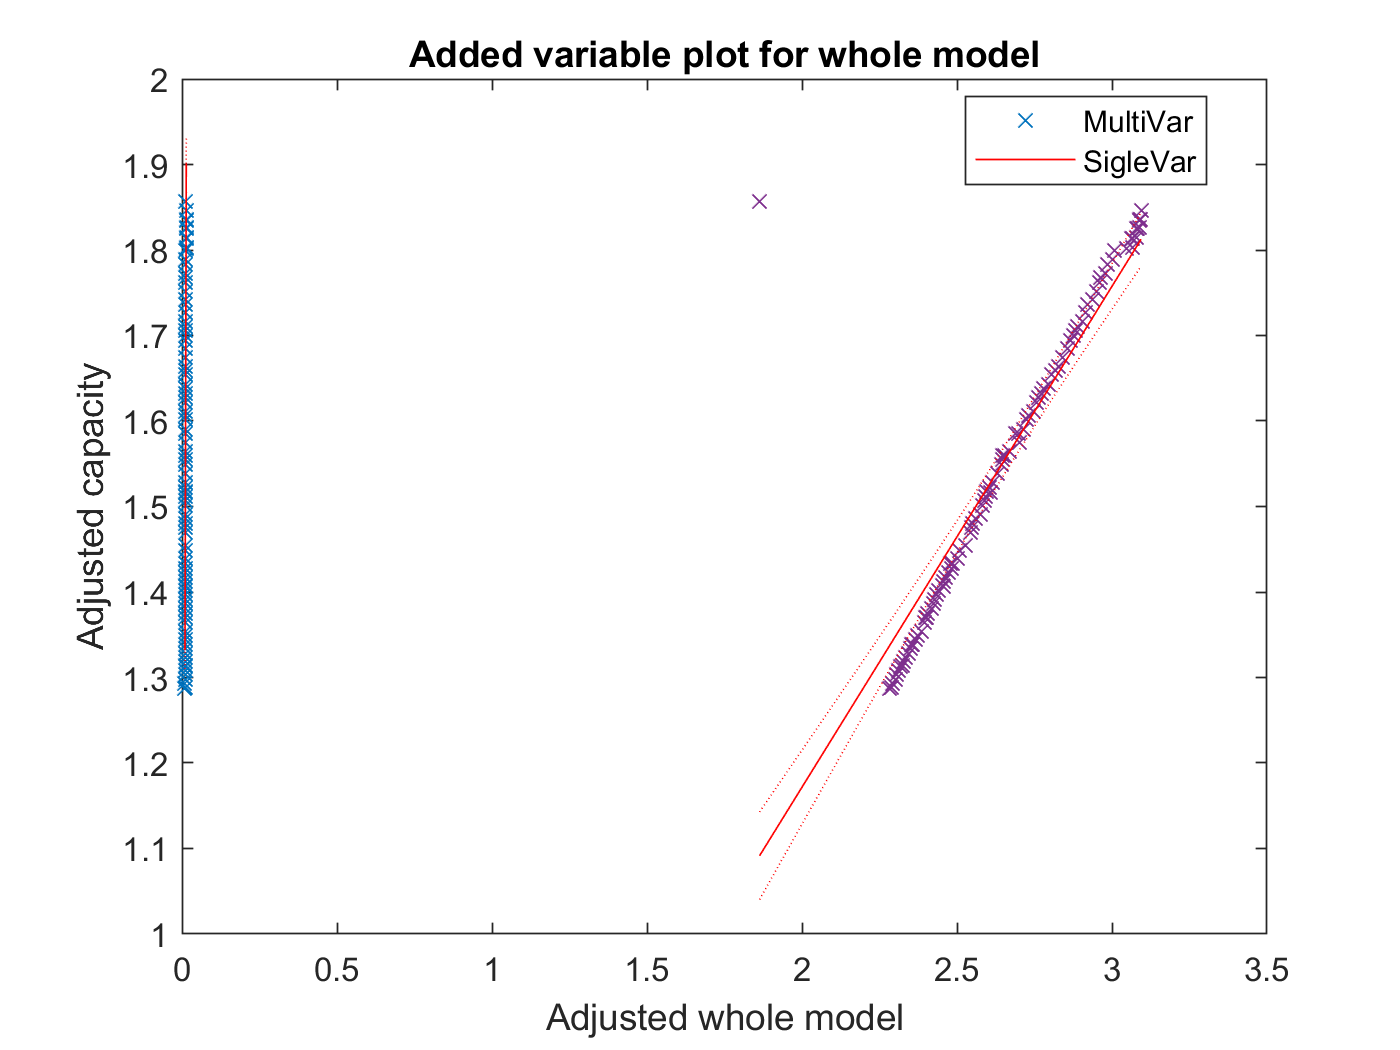


%% plot - model
figure
plot(mdl5)
hold on 
plot(mdlSingleX5)
hold off
legend('MultiVar','SigleVar')

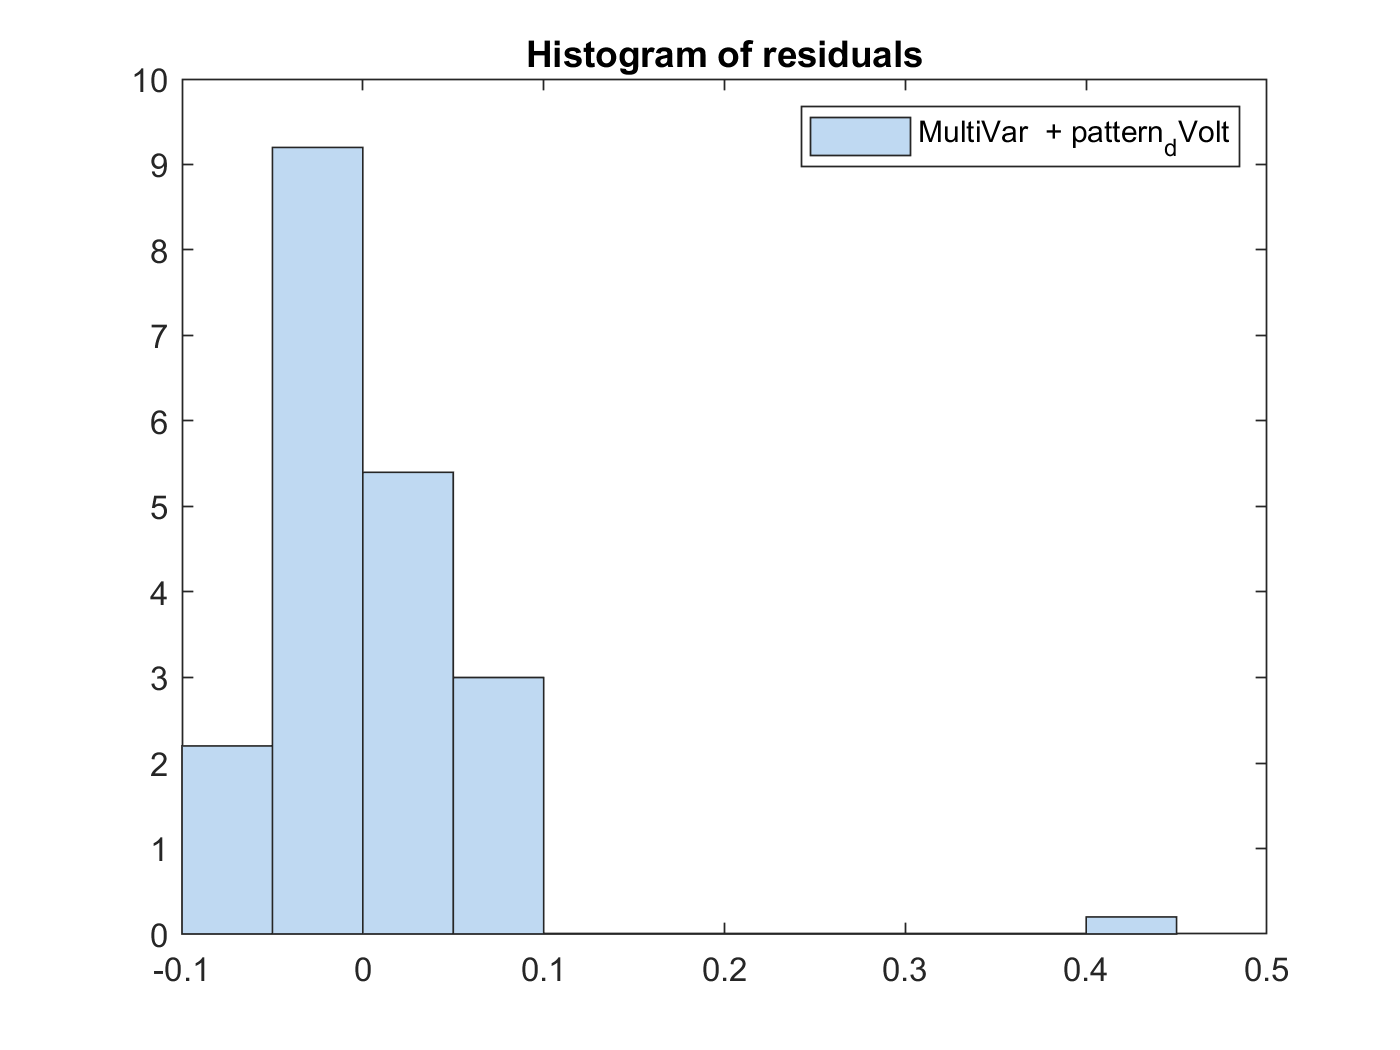



%% plot - residuals 
plotResiduals(mdl5)
legend('MultiVar  + pattern_dVolt')

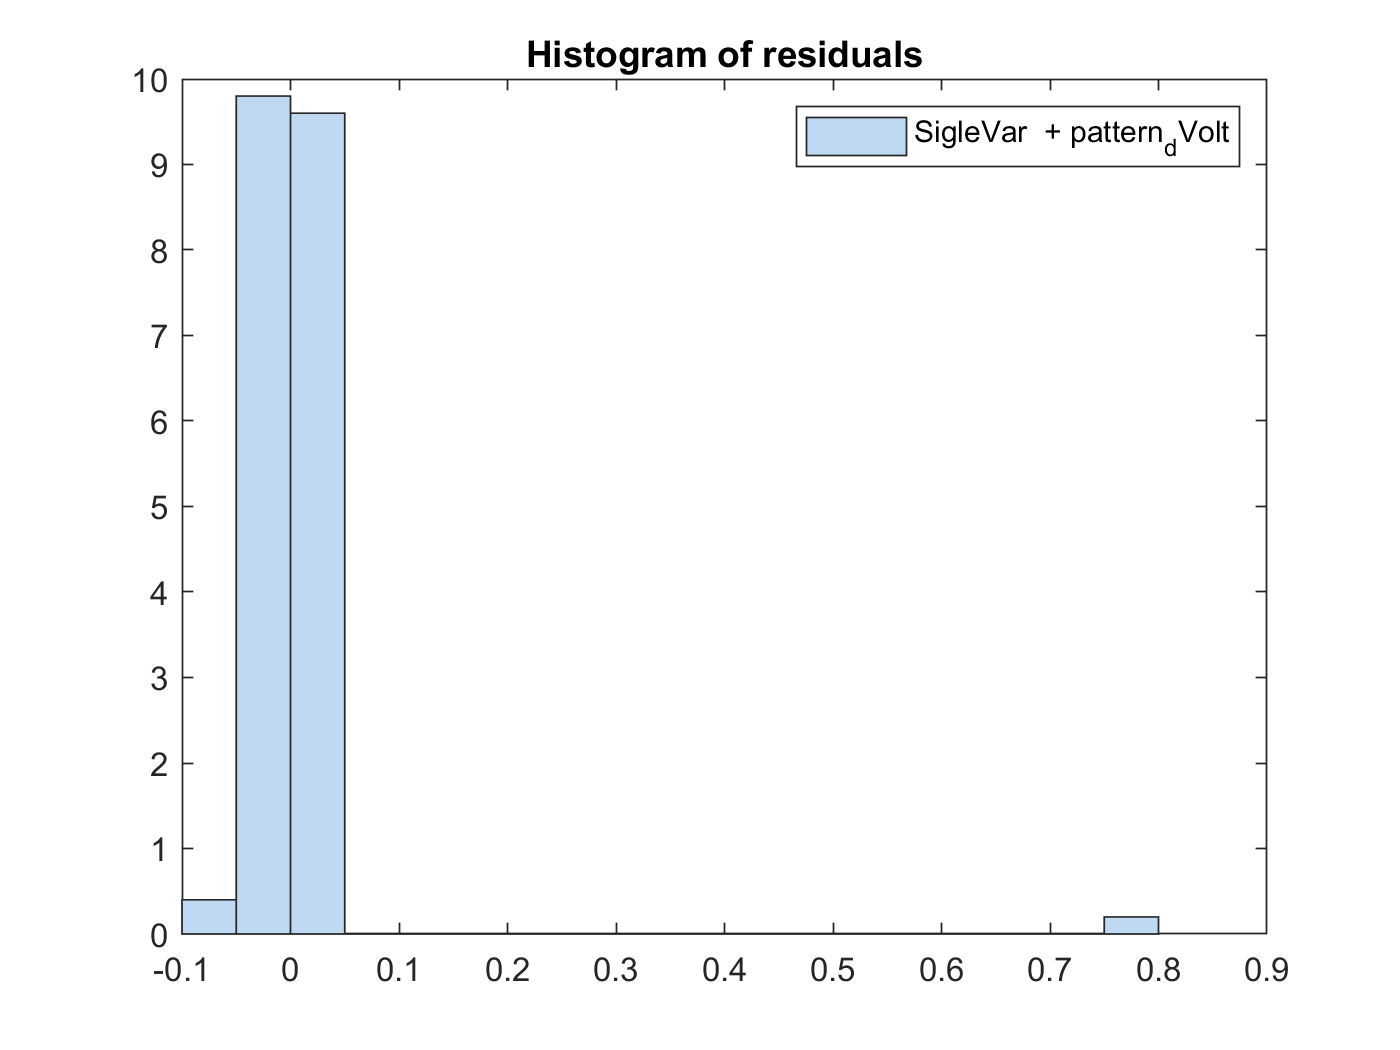

figure
plotResiduals(mdlSingleX5)
legend('SigleVar  + pattern_dVolt')

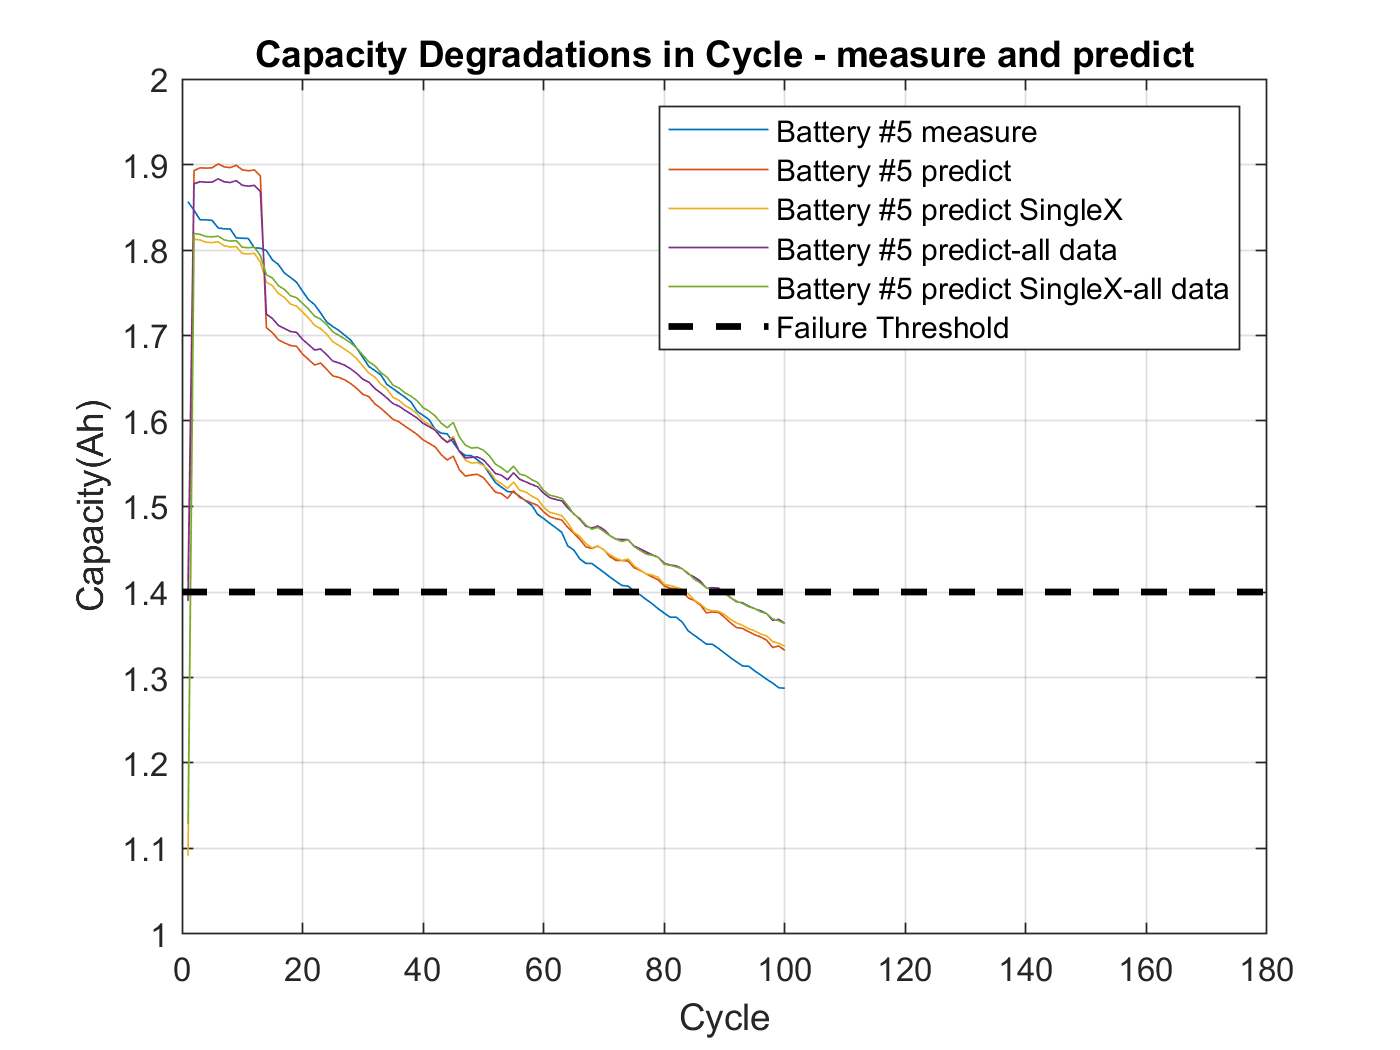

figure


%% plot - hat 
figure
plot(capacity05), hold on, plot(capacityHat5),plot(capacitySingleXHat5),plot(capacityHat),plot(capacitySingleXHat)
plot(0:180, 1.4*ones(1, 181),'k--','LineWidth', 2)
hold off, grid on
xlabel Cycle, ylabel Capacity(Ah)
legend('Battery #5 measure', 'Battery #5 predict', 'Battery #5 predict SingleX','Battery #5 predict-all data', 'Battery #5 predict SingleX-all data','Failure Threshold')
title('Capacity Degradations in Cycle - measure and predict')

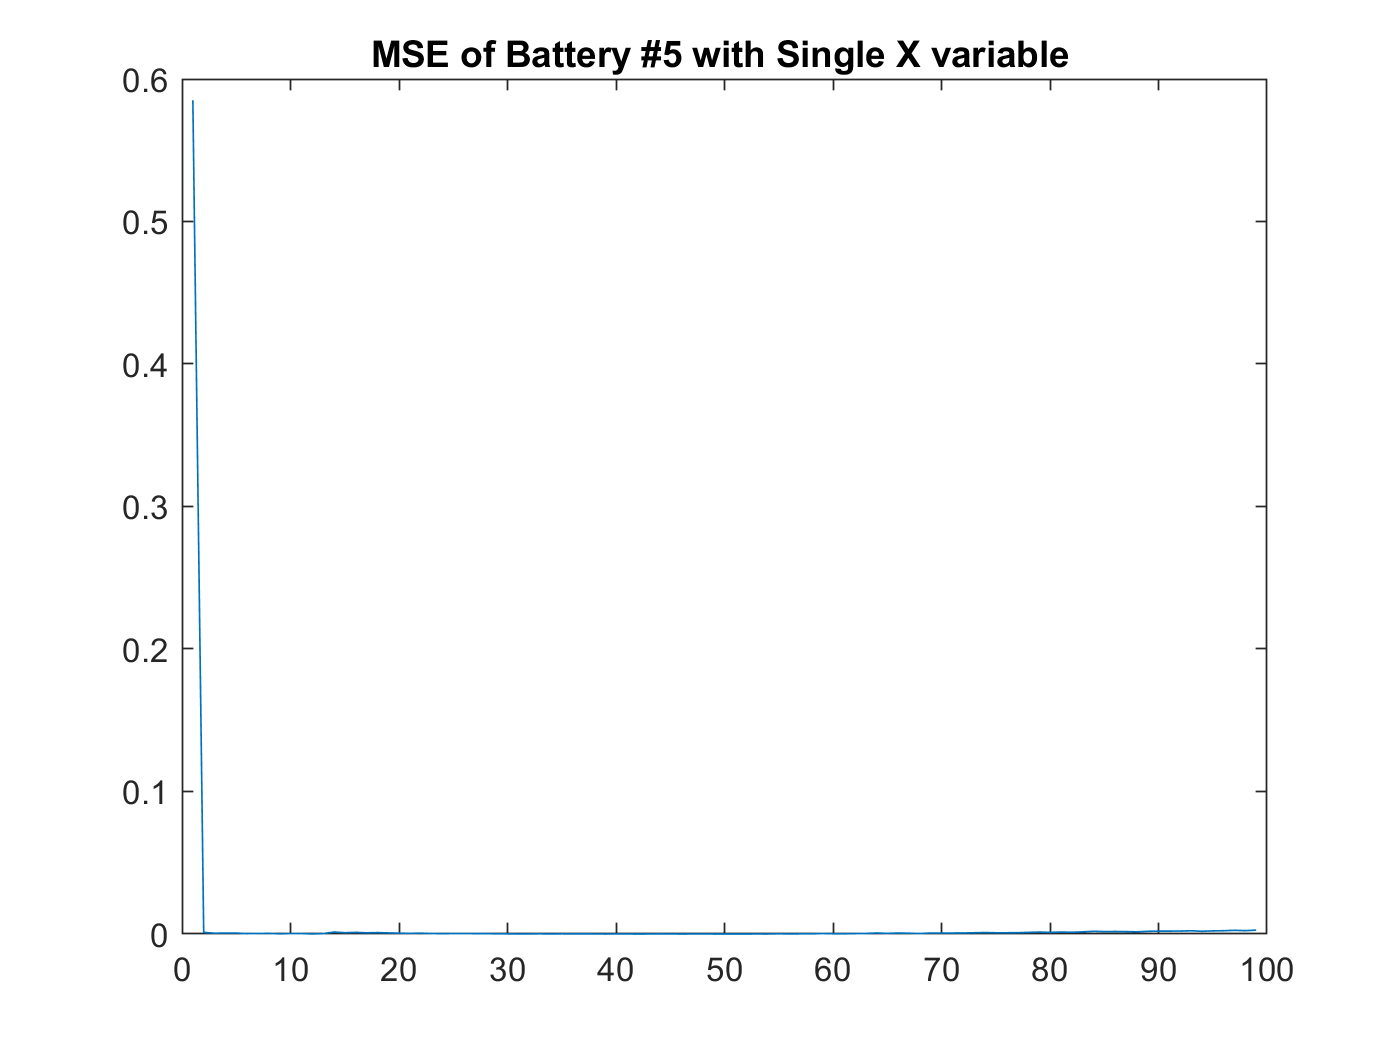


%%

% https://kr.mathworks.com/matlabcentral/answers/4064-rmse-root-mean-square-error
% https://kr.mathworks.com/matlabcentral/answers/234047-plot-mean-square-error

%%
% https://kr.mathworks.com/matlabcentral/answers/26944-plotting-rmse
% not works
%{
dt = 0.1;
k = length(capacity05);
capacityT5 = capacity05';
capacitySingleXHatT5 = capacitySingleXHat5';
err(k)=sqrt(sum(capacityT5(1:k,1)-capacitySingleXHatT5(1:k,1))^2/k);
t(k) = dt*k;  %simulation time, where dt is time for one increment of loop
%outside of loop:
figure
plot(err,t)
title('RMSE of Battery #5 with Single X variable ')
%}


%%
N = length(capacity05);
for i = 1:N-1
    mse_var(i) = mean((capacity05(i)-capacitySingleXHat5(i)).^2);
end
figure
plot(abs(mse_var));
title('MSE of Battery #5 with Single X variable ')


%% summary
% https://kr.mathworks.com/help/stats/linearmodel.html
anova(mdl5,'summary')

ans = 3×5 table
                SumSq     DF     MeanSq        F         pValue  
                ______    __    _________    ______    __________

    Total       3.0512    99      0.03082                        
    Model       2.6464     2       1.3232    317.07    2.8477e-43
    Residual    0.4048    97    0.0041732                        


anova(mdlSingleX5,'summary')

ans = 3×5 table
                 SumSq     DF     MeanSq        F        pValue  
                _______    __    _________    ______    _________

    Total        3.0512    99      0.03082                       
    Model        2.3956     1       2.3956    358.15    1.699e-34
    Residual    0.65551    98    0.0066889                       



mdl5.MSE

ans = 0.0042

mdl5.RMSE % 0.0131

ans = 0.0646

mdl5.SSE

ans = 0.4048

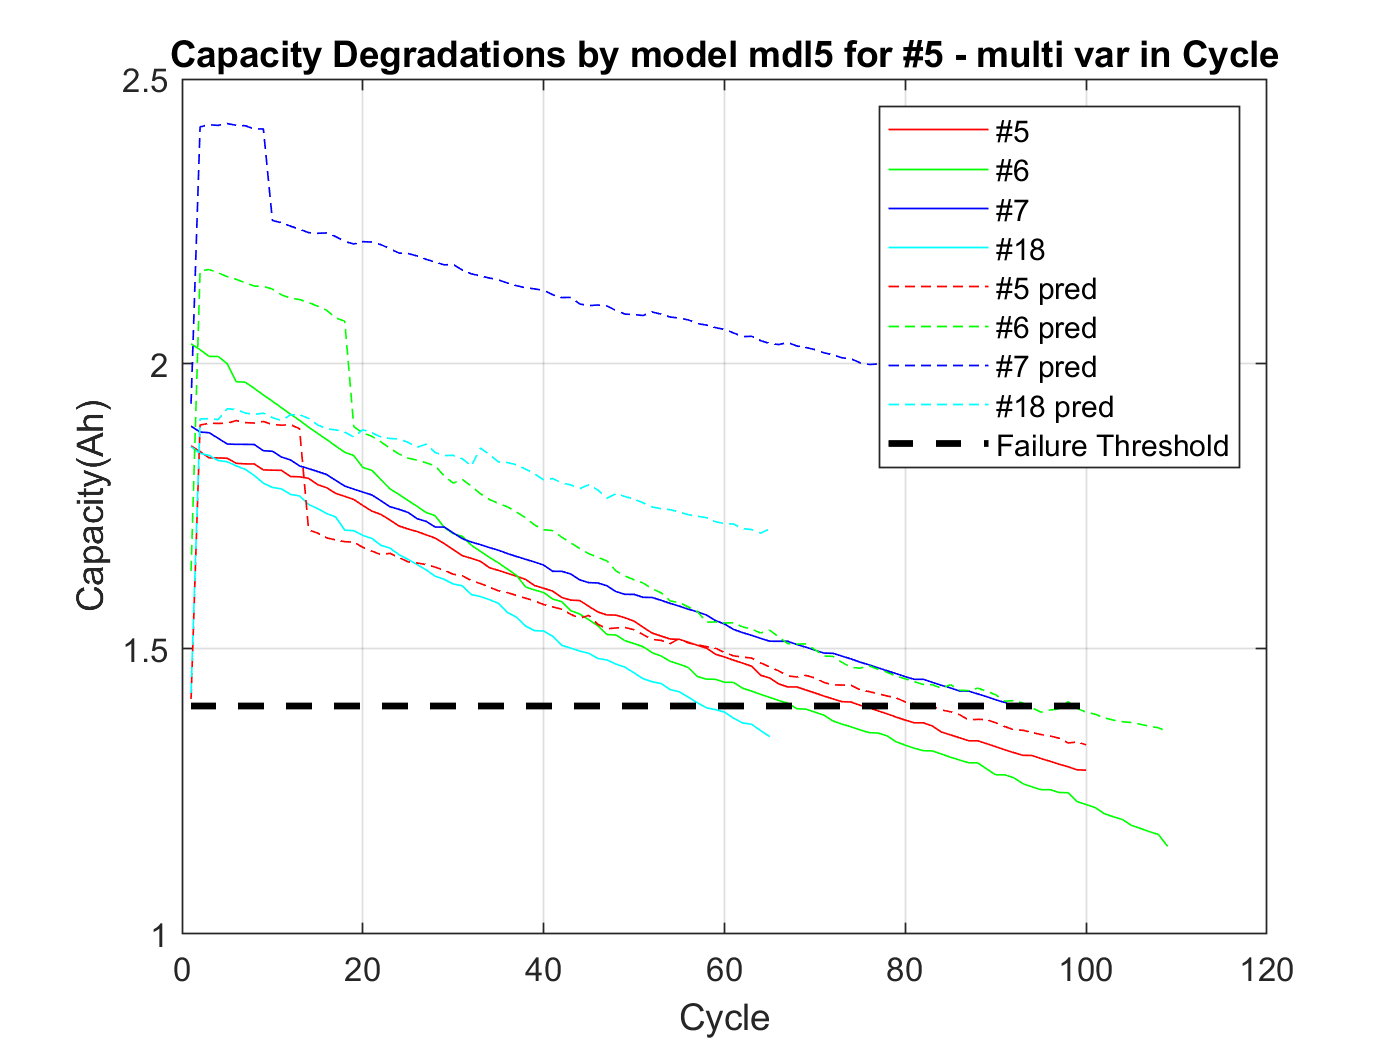

%% model mdl5 from battery 5 - predict other battery
pred6_by_mdl5 = predict(mdl5,regression_table06(:,{'cCcEndTimeSec','ohm','pattern_dVolt'}));
pred7_by_mdl5 = predict(mdl5,regression_table07(:,{'cCcEndTimeSec','ohm','pattern_dVolt'}));
pred18_by_mdl5 = predict(mdl5,regression_table18(:,{'cCcEndTimeSec','ohm','pattern_dVolt'}));

%% plot
cycle_number = length(capacity05);

figure
plot(capacity05,'r'), hold on, plot(capacity06,'g'), plot(capacity07,'b'), plot(capacity18,'c')
plot(capacityHat5,'r--'), hold on, plot(pred6_by_mdl5,'g--'), plot(pred7_by_mdl5,'b--'), plot(pred18_by_mdl5,'c--')
plot(1:cycle_number, 1.4*ones(1, cycle_number),'k--','LineWidth', 2)
hold off, grid on
xlabel Cycle, ylabel Capacity(Ah)
legend('#5', '#6', '#7', '#18','#5 pred', '#6 pred', '#7 pred', '#18 pred','Failure Threshold')
title('Capacity Degradations by model mdl5 for #5 - multi var in Cycle')

5+6, 5-6,6-5 

평가 5-6 <= mdl5, mdl6 ,mdl5-6, mdl6-5,mdl 5,6 

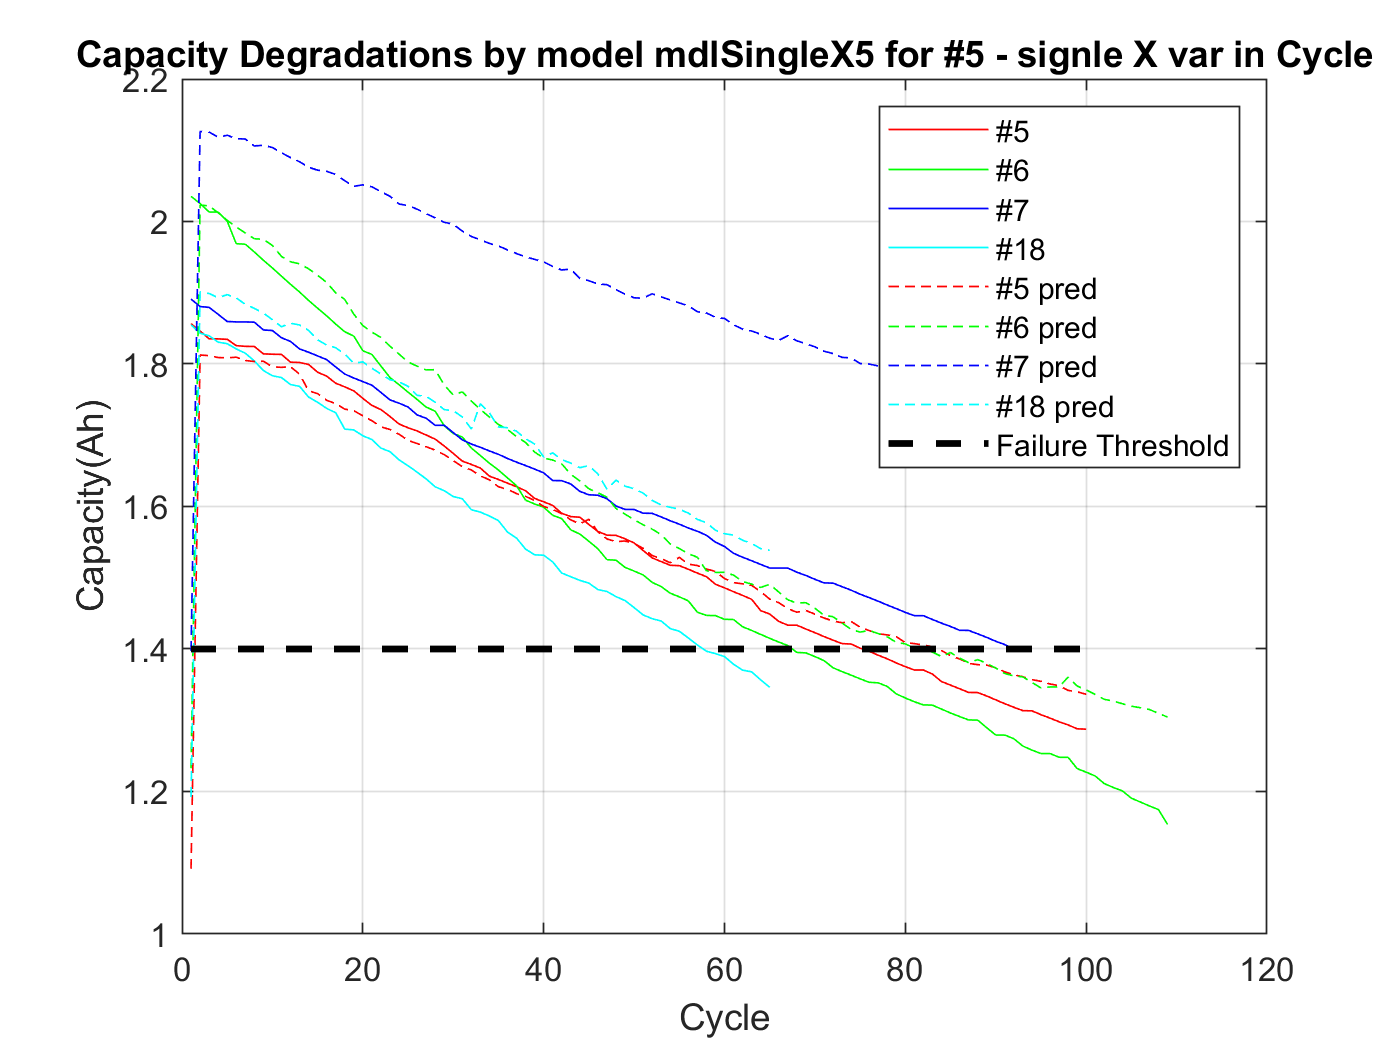

%% model from battery 5 - predict other battery
pred6_by_mdlSingleX5 = predict(mdlSingleX5,regression_table06(:,{'cCcEndTimeSec','pattern_dVolt'}));
pred7_by_mdlSingleX5 = predict(mdlSingleX5,regression_table07(:,{'cCcEndTimeSec','pattern_dVolt'}));
pred18_by_mdlSingleX5 = predict(mdlSingleX5,regression_table18(:,{'cCcEndTimeSec','pattern_dVolt'}));

%% plot
cycle_number = length(capacity05);

figure
plot(capacity05,'r'), hold on, plot(capacity06,'g'), plot(capacity07,'b'), plot(capacity18,'c')
plot(capacitySingleXHat5,'r--'), hold on, plot(pred6_by_mdlSingleX5,'g--'), plot(pred7_by_mdlSingleX5,'b--'), plot(pred18_by_mdlSingleX5,'c--')
plot(1:cycle_number, 1.4*ones(1, cycle_number),'k--','LineWidth', 2)
hold off, grid on
xlabel Cycle, ylabel Capacity(Ah)
legend('#5', '#6', '#7', '#18','#5 pred', '#6 pred', '#7 pred', '#18 pred','Failure Threshold')
title('Capacity Degradations by model mdlSingleX5 for #5 - signle X var in Cycle')




% 18 번 6번은 잘 적용이 안되고 특히 18번은 오류가 많다.
% 아무래도 cCcEndTimeSec 값이 해당 배터리에서 적용이 잘 안되는 것 같다.



% https://kr.mathworks.com/matlabcentral/answers/386493-rmse-between-two-variables
mdl5.RMSE

ans = 0.0646

mdl6.RMSE

ans = 0.0624

mdl7.RMSE

ans = 0.0626

mdl18.RMSE

ans = 0.0760


RMSE_5 = sqrt(mean(( capacity05 - capacityHat5 ).^2))

RMSE_5 = 0.0636

RMSE_6 = sqrt(mean(( capacity06 - capacityHat6 ).^2))

RMSE_6 = 0.0615

RMSE_7 = sqrt(mean(( capacity07 - capacityHat7 ).^2))

RMSE_7 = 0.0615

RMSE_18 = sqrt(mean(( capacity18 - capacityHat18 ).^2))

RMSE_18 = 0.0742


RMSE_5_by_mdl5 = sqrt(mean(( capacity05 - capacityHat5 ).^2))

RMSE_5_by_mdl5 = 0.0636

RMSE_6_by_mdl5 = sqrt(mean(( capacity06 - pred6_by_mdl5' ).^2))

RMSE_6_by_mdl5 = 0.1399

RMSE_7_by_mdl5 = sqrt(mean(( capacity07 - pred7_by_mdl5' ).^2))

RMSE_7_by_mdl5 = 0.4964

RMSE_18_by_mdl5 = sqrt(mean(( capacity18 - pred18_by_mdl5' ).^2))

RMSE_18_by_mdl5 = 0.2500


mdlSingleX5.RMSE

ans = 0.0818

mdlSingleX6.RMSE

ans = 0.0880

mdlSingleX7.RMSE

ans = 0.0869

mdlSingleX18.RMSE

ans = 0.1052

% https://kr.mathworks.com/matlabcentral/answers/286146-why-rmse-obtained-by-fitlm-in-matlab-does-not-match-with-rmse-calculated-in-excel
% As you can see, dividing by the degrees of freedom is what fitlm must be doing.
% sqrt(sum((y - lm.predict(x)).^2/100)) 
% sqrt(sum((y - lm.predict(x)).^2/100))  -> dividing by the degrees of freedom
RMSE_SingleX_5 = sqrt(mean(( capacity05 - capacitySingleXHat5 ).^2))

RMSE_SingleX_5 = 0.0810

RMSE_SingleX_6 = sqrt(mean(( capacity06 - capacitySingleXHat6 ).^2))

RMSE_SingleX_6 = 0.0872

RMSE_SingleX_7 = sqrt(mean(( capacity07 - capacitySingleXHat7 ).^2))

RMSE_SingleX_7 = 0.0859

RMSE_SingleX_18 = sqrt(mean(( capacity18 - capacitySingleXHat18 ).^2))

RMSE_SingleX_18 = 0.1036


RMSE_5_by_mdlSingleX5 = sqrt(mean(( capacity05 - capacitySingleXHat5 ).^2))

RMSE_5_by_mdlSingleX5 = 0.0810

RMSE_6_by_mdlSingleX5 = sqrt(mean(( capacity06 - pred6_by_mdlSingleX5' ).^2))

RMSE_6_by_mdlSingleX5 = 0.1071

RMSE_7_by_mdlSingleX5 = sqrt(mean(( capacity07 - pred7_by_mdlSingleX5' ).^2))

RMSE_7_by_mdlSingleX5 = 0.3046

RMSE_18_by_mdlSingleX5 = sqrt(mean(( capacity18 - pred18_by_mdlSingleX5' ).^2))

RMSE_18_by_mdlSingleX5 = 0.1572